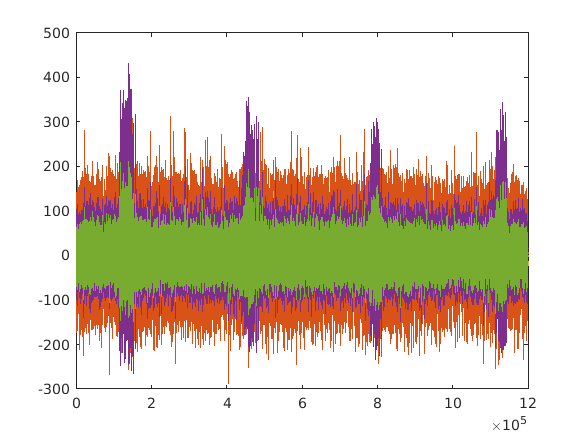

% MODE: BIPOLAR
% pos: e22
% neg: e64
% 
% WAVEFORM: 
% SHAPE: SQUARE BIPHASIC pos/neg
% DURATION/PHASE: 100 us ?
% AMPLITUDE/PHASE: 200 uA
% 
% ----------------------------
%
% 
% e22: labled ictal events only; interic1   tal events are hidden in the baseline noise.
% 
% e64: labeled ictal events only; possibly, interictal events are hidden in the baseline noise.
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Author: LilyHeAsamiko
% 
data1 = load('20171005_slice01_01_CTRL1_12.mat');
data2 = load('20171005_slice01_01_CTRL1_13.mat');
data3 = load('20171005_slice01_01_CTRL1_14.mat');
data4 = load('20171005_slice01_01_CTRL1_22.mat');

datalabel = load('20171005_slice01_01_CTRL1_12_ICTAL_LABELS.mat');

% data1 = load('D:\TUT\Medical\biophysics\NolinearTimeSeriesAnalysis-new\data\20171005\01\20171005_01_mat_files\20171005_slice01_01_CTRL1_12.mat');
% data2 = load('D:\TUT\Medical\biophysics\NolinearTimeSeriesAnalysis-new\data\20171005\01\20171005_01_mat_files\20171005_slice01_01_CTRL1_13.mat');
% data3 = load('D:\TUT\Medical\biophysics\NolinearTimeSeriesAnalysis-new\data\20171005\01\20171005_01_mat_files\20171005_slice01_01_CTRL1_14.mat');
% data4 = load('D:\TUT\Medical\biophysics\NolinearTimeSeriesAnalysis-new\data\20171005\01\20171005_01_mat_files\20171005_slice01_01_CTRL1_22.mat');
% 
% datalabel = load('D:\TUT\Medical\biophysics\NolinearTimeSeriesAnalysis-new\data\20171005\01\20171005_01_LABELS\20171005_slice01_01_CTRL1_12_ICTAL_LABELS.mat');

fs = data1.fs;
MEA1 = data1.data;
MEA2 = data2.data;
MEA3 = data3.data;
MEA4 = data4.data;

ictals = table2array(datalabel.labels);
N = length(MEA1);%sample number
T = N/fs; %600s
bin = N/T; %samples per bin(1s)
N_bin = N/bin; % bin number
ch = 1;%12 13 14 22

% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% % tonic seizure
% % 3min , 1min pre-seizure, 1min seizure, 1min post-seizure
% MEA0 = data0.data0.data;
% MEA1 = data.data.data;
% seizures0 = table2array(data0.data0.labels);
% seizure1 = table2array(data.data.labels);
% fs = data0.data0.fs
% 
% N = length(MEA0);%sample number
% T = N/fs; %180 s
% bin = N/T; %samples per bin(1s)
% N_bin = N/bin; % bin number
% ch = 1;%1 0

MEA_avg = mean([MEA1, MEA2, MEA3, MEA4], 2);
figure
%% onset detection
% average of the multi-channels

plot(MEA1)
hold on
plot(MEA2)
hold on
plot(MEA3)
hold on
plot(MEA4)
hold on
plot(MEA_avg)


MEA_t = [MEA1 MEA2 MEA3 MEA4 MEA_avg];
for win = 1: N_bin    
    MEA_t_avg(win, :) = mean(MEA_t((win-1)*bin+1:(win-1)*bin+bin,:),1);
end

% %%%%%%%
% %another
% figure
% plot(MEA0)
% hold on
% plot(MEA1)
% 
% MEA_t = [MEA0 MEA1];
% for win = 1: N_bin    
%     MEA_t_avg(win, :) = mean(MEA_t((win-1)*bin/2+1:(win-1)*bin/2+bin,:),1);
% end

% onset based on decorrelation time: the first t ensures, local minimum of
% autocorrelation: abs(corr< 1/e),  here let e be 2
[rho,pval] = corr(MEA_t_avg');
tau = autocorr(MEA_t_avg(:)', 'NumLags', 600)

tau =     1.0000   -0.5092    0.0277   -0.0409    0.0026    0.0472   -0.0050   -0.0060    0.0015    0.0080   -0.0102    0.0155    0.0194   -0.0769    0.1111   -0.0851    0.0324    0.0052    0.0084    0.0058    0.0211   -0.0831    0.0715   -0.0214    0.0154   -0.0014   -0.0022   -0.0078    0.0095    0.0147   -0.0043    0.0162   -0.0317    0.0414   -0.0212   -0.0431    0.1153   -0.0769    0.0083   -0.0138    0.0074    0.0260    0.0277   -0.0492    0.0441   -0.0628    0.0441    0.0073   -0.0070    0.0165


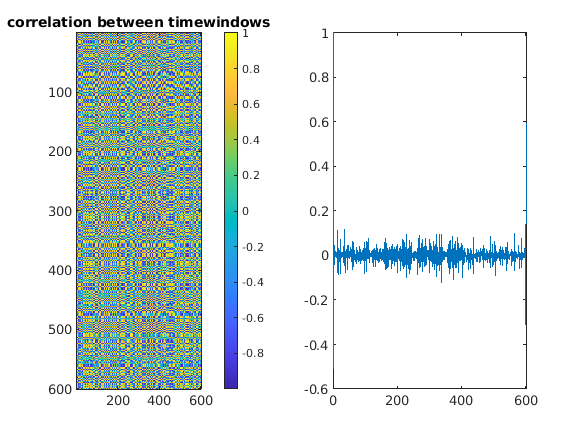

figure,
subplot(1,2,1)  
%pcolor(rho);
imagesc(rho)
title('correlation between timewindows');
colorbar
subplot(1,2,2)
plot(tau);

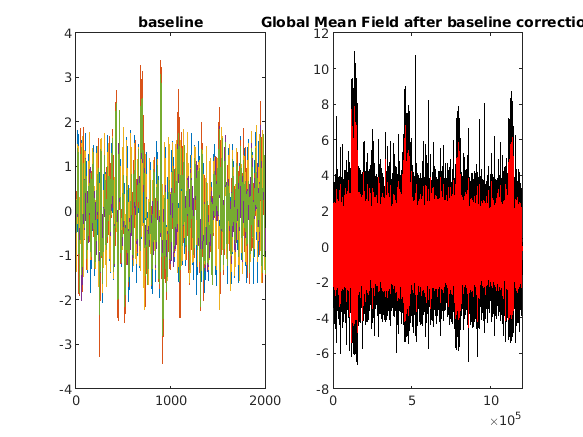

rho_dec = min(find(rho < 0.5));
rho_dec1 = min(find(tau < 0.5));
t_onset = rho_dec; %same as rho_dec1       


%[minr, t_row] = min(abs(rho));
%[minrho, t_col] = min(minr);
%t_onset = min(t_col,t_row(t_col));

% onset based on ictals label
% onset_lb = floor(ictals(1));
% if t_onset > onset_lb
%    t_onset = onset_lb; 
% end
onset = (t_onset-1)*fs;

MEA_seizure = MEA_t(onset+1: N,:); 
MEA_ch = MEA_seizure(:,1);
%  baseline_corrected
MEA_seizure0 = MEA_seizure - repmat(mean(MEA_t_avg(1: t_onset,:), 1),size(MEA_seizure,1), 1);
% Z-score Normalization
MEA_seizure = MEA_seizure0./std(MEA_seizure0, 1);
% GMFP
m = mean(MEA_seizure, 2);
GMF = m;
k = length(MEA_seizure);
%GMF = sqrt(mean((MEA_seizure-repmat(m, 1, size(MEA_seizure, 2))).^2,2)); 

figure,
subplot(1, 2, 1)
plot(1:onset,MEA_seizure(1:onset,:));
%note wrong: xlim([0 onset+10])
%xticks(int32(1: k/7: onset))
title('baseline');
subplot(1, 2, 2)
plot(onset+1: N, MEA_seizure,'k');
hold on;
plot(onset+1: N, GMF,'r');
%xlim([onset+1 k+10+onset+1])
%xticks(int32(onset+1: k/5: N))
%xticklabels(num2str(onset+1: k/5: N))
title('Global Mean Field after baseline correction');

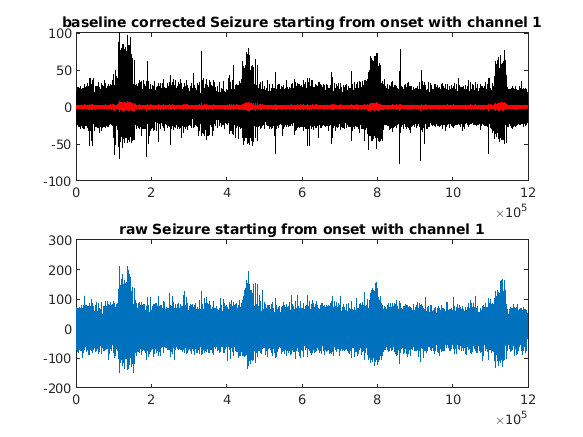


MEAy_ch = MEA_seizure0(:,ch);
Pnts = length(MEAy_ch);
figure,
subplot(2, 1, 1)
plot(MEAy_ch, 'k')
hold on
plot(GMF,'r')
title(['baseline corrected Seizure starting from onset with channel ',num2str(ch)]);
subplot(2, 1, 2)
plot(MEA_avg(onset+1: N))
title(['raw Seizure starting from onset with channel ',num2str(ch)]);

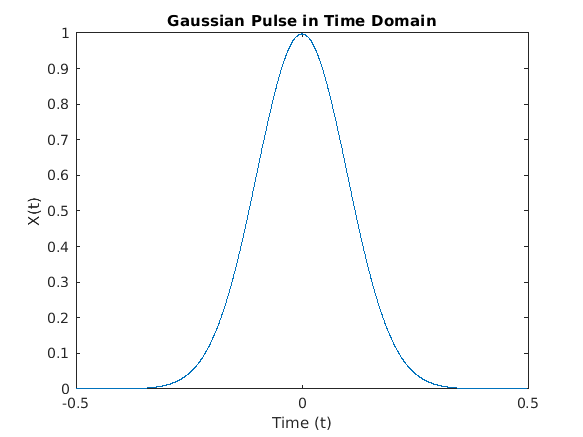

%% count spikes 
threshold = 10;% spike: >10 muV
%threshold = 20;
delta = [0.5, 3];
theta = [4, 7];
alpha = [8, 12];
mu = [7.5, 12.5];
SMR = [12.5, 15.5];
beta = [16, 31];
gamma = [32, 100];
HF = 70;
ripple = [80, 250];
fastripple= 251;

t = -0.5:1/fs:0.5;  % Time vector 
L = length(t)-1;      % Signal length
X = 1/(4*sqrt(2*pi*0.01))*(exp(-t(1:L).^2/(2*0.01)));

figure,
plot(t(1:L),X)
title('Gaussian Pulse in Time Domain')
xlabel('Time (t)')
ylabel('X(t)')

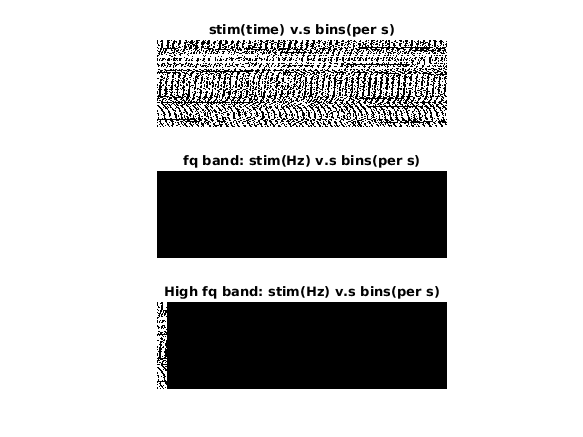

%single spikes
%Ns = length(MEAy_ch(MEAy_ch > threshold));

N_bin = ceil(Pnts/bin);
chf_bin_d = zeros(N_bin, bin); 
chf_bin_th = zeros(N_bin, bin); 
chf_bin_a = zeros(N_bin, bin); 
chf_bin_m = zeros(N_bin, bin); 
chf_bin_s = zeros(N_bin, bin); 
chf_bin_b = zeros(N_bin, bin); 
chf_bin_g = zeros(N_bin, bin); 
chf_bin_h = zeros(N_bin, bin); 
chf_bin_r = zeros(N_bin, bin); 
chf_bin_fr = zeros(N_bin, bin); 

chn_bin = zeros(N_bin, bin);
chf_bin = zeros(N_bin, bin);
MEAs_chft = zeros(N_bin, 0.5*bin);
MEAs_chsd = zeros(N_bin, 0.5*bin);

Ns_chn_bin = zeros(N_bin,1); 
Nsft_chn_bin = zeros(N_bin,1); 
Nssd_chn_bin = zeros(N_bin,1); 
MEAs_chf = zeros(N_bin, bin);   

fn = 0:bin-1;
f = 1.0*double(fn)/double(bin-1);

Chf_bin_d = find(f > (delta(1)/fs) & f < (delta(2)/fs));
Chf_bin_th = find(f > (theta(1)/fs) & f < (theta(2)/fs));
Chf_bin_a = find(f > (alpha(1)/fs) & f < (alpha(2)/fs));
Chf_bin_m = find(f > (mu(1)/fs) & f < (mu(2)/fs));
Chf_bin_s = find(f > (SMR(1)/fs) & f < (SMR(2)/fs));
Chf_bin_b = find(f > (beta(1)/fs) & f < (beta(2)/fs));
Chf_bin_g = find(f > (gamma(1)/fs) & f < (gamma(2)/fs));
Chf_bin_h = find(f > HF/fs);
Chf_bin_r = find(f > (ripple(1)/fs) & f < (ripple(2)/fs));
Chf_bin_fr = find(f > fastripple/fs);

if mod(Pnts, bin) > 0
    N_bin = ceil(Pnts/bin);
else
    N_bin = Pnts/bin;
end



%per second                       
for n = 1: N_bin
%    nn = 2*n-1;
    if n == N_bin
       if length(bin*(n-1)+1:Pnts) < bin
            MEAs_chn = [MEA_ch(bin*(n-1)+1:Pnts); zeros(bin-length(bin*(n-1)+1:Pnts), 1)];
       else
            MEAs_chn = MEA_ch(bin*(n-1)+1:Pnts);
       end
       MEAs_chft(n,:) = MEAs_chn(1:0.5*bin)'; %
       MEAs_chsd(n,:) = MEAs_chn(0.5*bin+1:bin)';
%         %test
%         MEAs_testn = MEA_test(bin*(n-1)+1:Pnts);
%         MEAs_testft = MEA_test(0.5*bin*(nn-1)+1:0.5*bin*nn);
%         MEAs_testsd = MEA_test(0.5*bin*nn+1:Pnts);
    else
       MEAs_chn = MEA_ch(bin*(n-1)+1:bin*n);
       MEAs_chft(n,:) = MEAs_chn(1:0.5*bin)'; %
       MEAs_chsd(n,:) = MEAs_chn(0.5*bin+1:bin)';
%        MEAs_chft = MEA_ch(0.5*bin*(n-1)+1:0.5*bin*n);
%        MEAs_chsd = MEA_ch(0.5*bin*n+1:0.5*bin*(n+1));
        %test
%         MEAs_testn = MEA_test(bin*(n-1)+1:bin*n);
%         MEAs_testft = MEA_test(0.5*bin*(nn-1)+1:0.5*bin*nn);
%         MEAs_testsd = MEA_test(0.5*bin*nn+1:0.5*bin*(nn+1));        
    end
    size(fft(MEAs_chn'));
    if length(fft(MEAs_chn))< length(MEAs_chf(n,:))
        FFT_MEAs_chn = [fft(MEAs_chn') zeros(1, length(MEAs_chf(n,:))-length(fft(MEAs_chn)))];
        EXT_MEAs = [MEAs_chn' zeros(1, length(MEAs_chf(n,:))-length(MEAs_chn))];
    else
        FFT_MEAs_chn = fft(MEAs_chn');
        EXT_MEAs = MEAs_chn';
    end
    size(X);
    MEAs_chf(n,:) = FFT_MEAs_chn.*X;
  
%!!
%     chf_bin_d(n,:) = abs(MEAs_chf(n,:)) > delta(1) & abs(MEAs_chf(n,:)) < delta(2);
%     chf_bin_th(n,:) = abs(MEAs_chf(n,:)) > theta(1) & abs(MEAs_chf(n,:)) < theta(2);
%     chf_bin_a(n,:) = abs(MEAs_chf(n,:)) > alpha(1) & abs(MEAs_chf(n,:)) < alpha(2);
%     chf_bin_m(n,:) = abs(MEAs_chf(n,:)) > mu(1) & abs(MEAs_chf(n,:)) < mu(2);
%     chf_bin_s(n,:) = abs(MEAs_chf(n,:)) > SMR(1) & abs(MEAs_chf(n,:)) < SMR(2);
%     chf_bin_b(n,:) = abs(MEAs_chf(n,:)) > beta(1) & abs(MEAs_chf(n,:)) < beta(2);
%     chf_bin_g(n,:) = abs(MEAs_chf(n,:)) > gamma(1) & abs(MEAs_chf(n,:)) < gamma(2);
    
    chf_bin_h(n, Chf_bin_h) = abs(MEAs_chf(n, Chf_bin_h));
    chf_bin_r(n, Chf_bin_r) = abs(MEAs_chf(n, Chf_bin_r));
    chf_bin_fr(n, Chf_bin_fr) = abs(MEAs_chf(n, Chf_bin_fr));
    chf_bin_h(n,abs(EXT_MEAs) > threshold) = abs(MEAs_chf(n,abs(EXT_MEAs) > threshold))*(sum(abs(EXT_MEAs) > threshold)>=6);
    chf_bin_r(n,abs(EXT_MEAs) > threshold) = abs(MEAs_chf(n,abs(EXT_MEAs) > threshold))*(sum(abs(EXT_MEAs) > threshold)>=6);
    chf_bin_fr(n, abs(EXT_MEAs) > threshold) = abs(MEAs_chf(n,abs(EXT_MEAs) > threshold))*(sum(abs(EXT_MEAs) > threshold)>=6);
    chf_bin_d(n,Chf_bin_d) = abs(MEAs_chf(n, Chf_bin_d));
    chf_bin_th(n,Chf_bin_th) = abs(MEAs_chf(n, Chf_bin_th));
    chf_bin_a(n,Chf_bin_a) = abs(MEAs_chf(n, Chf_bin_a));
    chf_bin_m(n,Chf_bin_m) = abs(MEAs_chf(n, Chf_bin_m));
    chf_bin_s(n,Chf_bin_s) = abs(MEAs_chf(n, Chf_bin_s));
    chf_bin_b(n,Chf_bin_b) = abs(MEAs_chf(n, Chf_bin_b));
    chf_bin_g(n, Chf_bin_g) = abs(MEAs_chf(n, Chf_bin_g));

   
    Ns_chn_bin(n) = length(MEAs_chn(abs(MEAs_chn) > threshold));
    Nsft_chn_bin(n) = length(MEAs_chft(abs(MEAs_chft) > threshold));
    Nssd_chn_bin(n) = length(MEAs_chsd(abs(MEAs_chsd) > threshold));    
    chn_bin(n,:) = EXT_MEAs.*(abs(EXT_MEAs) > threshold); 
    if n == N_bin 
        break;
    end
end
[normalizedACF, lags]= autocorr(chn_bin(:),'NumLags',573);
chns_rho = normalizedACF;
[normalizedACF, lags]= autocorr(MEAs_chf(:),'NumLags',573);
chf_rho = normalizedACF;
% [chnsd_rho,chnsd_p] = corr(chf_bin_d);
% [chnsth_rho,chnsth_p] = corr(chf_bin_th);
% [chnsa_rho,chnsa_p] = corr(chf_bin_a);
% [chnsm_rho,chnsm_p] = corr(chf_bin_m);
% [chnss_rho,chnss_p] = corr(chf_bin_s);
% [chnsb_rho,chnsb_p] = corr(chf_bin_b);
% [chnsg_rho,chnsg_p] = corr(chf_bin_g);

Ns = sum(Ns_chn_bin);

[normalizedACF, lags]= autocorr(chf_bin_d(:),'NumLags',573);
chnsd_rho = normalizedACF;
[normalizedACF, lags]= autocorr(chf_bin_th(:),'NumLags',573);
chnsth_rho = normalizedACF;
[normalizedACF, lags]= autocorr(chf_bin_a(:),'NumLags',573);
chnsa_rho = normalizedACF;
[normalizedACF, lags]= autocorr(chf_bin_m(:),'NumLags',573);
chnsm_rho = normalizedACF;
[normalizedACF, lags]= autocorr(chf_bin_s(:),'NumLags',573);
chnss_rho = normalizedACF;
[normalizedACF, lags]= autocorr(chf_bin_b(:),'NumLags',573);
chnsb_rho = normalizedACF;
[normalizedACF, lags]= autocorr(chf_bin_g(:),'NumLags',573);
chnsg_rho = normalizedACF;
[normalizedACF, lags]= autocorr(chf_bin_h(:),'NumLags',573);
chnsh_rho = normalizedACF;
[normalizedACF, lags]= autocorr(chf_bin_r(:),'NumLags',573);
chnsr_rho = normalizedACF;
[normalizedACF, lags]= autocorr(chf_bin_fr(:),'NumLags',573);
chnsfr_rho = normalizedACF;
% [chnsth_rho,chnsth_p] = mscohere(chf_bin_th, chf_bin_th);
% [chnsa_rho,chnsa_p] = mscohere(chf_bin_a, chf_bin_a);
% [chnsm_rho,chnsm_p] = mscohere(chf_bin_m, chf_bin_m);
% [chnss_rho,chnss_p] = mscohere(chf_bin_s, chf_bin_s);
% [chnsb_rho,chnsb_p] = mscohere(chf_bin_b, chf_bin_b);
% [chnsg_rho,chnsg_p] = mscohere(chf_bin_g, chf_bin_g);
% [chnsh_rho,chnsh_p] = mscohere(chf_bin_h, chf_bin_h);
% [chnsr_rho,chnsr_p] = mscohere(chf_bin_r, chf_bin_r);
% [chnsfr_rho,chnsfr_p] = mscohere(chf_bin_fr, chf_bin_fr);

chnsd_rho(isnan(chnsd_rho)) = 0;
chnsth_rho(isnan(chnsth_rho)) = 0;
chnsa_rho(isnan(chnsa_rho)) = 0;
chnsm_rho(isnan(chnsm_rho)) = 0;
chnss_rho(isnan(chnss_rho)) = 0;
chnsb_rho(isnan(chnsb_rho)) = 0;
chnsg_rho(isnan(chnsg_rho)) = 0;
chnsh_rho(isnan(chnsh_rho)) = 0;
chnsr_rho(isnan(chnsr_rho)) = 0;
chnsfr_rho(isnan(chnsfr_rho)) = 0;

%0 black
figure,
subplot(3,1,1)
imshow(chn_bin==0);
title('stim(time) v.s bins(per s)')
subplot(3,1,2)
imshow(abs(MEAs_chf) == 0);
title('fq band: stim(Hz) v.s bins(per s)')
subplot(3,1,3)
imshow(abs(chf_bin_h) == 0);
title('High fq band: stim(Hz) v.s bins(per s)')

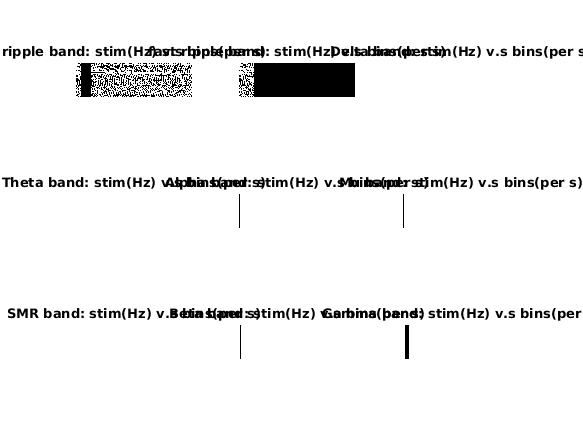



figure,
subplot(3,3,1)
imshow(chf_bin_r==0);
title('ripple band: stim(Hz) v.s bins(per s)')
subplot(3,3,2)
imshow(chf_bin_fr==0);
title('fast ripple band: stim(Hz) v.s bins(per s)')
subplot(3,3,3)
imshow(chf_bin_d==0);
title('Delta band: stim(Hz) v.s bins(per s)')
subplot(3,3,4)
imshow(chf_bin_th==0);
title('Theta band: stim(Hz) v.s bins(per s)')
subplot(3,3,5)
imshow(chf_bin_a==0);
title('Alpha band: stim(Hz) v.s bins(per s)')
subplot(3,3,6)
imshow(chf_bin_m==0);
title('Mu band: stim(Hz) v.s bins(per s)')
subplot(3,3,7)
imshow(chf_bin_s==0);
title('SMR band: stim(Hz) v.s bins(per s)')
subplot(3,3,8)
imshow(chf_bin_b==0);
title('Beta band: stim(Hz) v.s bins(per s)')
subplot(3,3,9)
imshow(chf_bin_g==0);
title('Gamma band: stim(Hz) v.s bins(per s)')

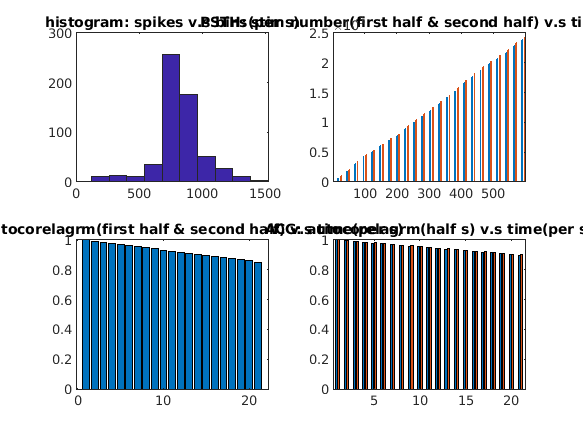

figure,
subplot(2,2,1)
hist(Ns_chn_bin);
title('histogram: spikes v.s bins(per s)')
subplot(2,2,2)
bar([Nsft_chn_bin,Nssd_chn_bin]);
title('PSTH: stim number(first half & second half) v.s time(per s)')
subplot(2,2,3)
bar(autocorr([Nsft_chn_bin', Nssd_chn_bin']));
title('ACG: autocorelagrm(first half & second half) v.s time(per s)')
subplot(2,2,4)
bar([autocorr(Nsft_chn_bin), autocorr(Nssd_chn_bin)]);
title('ACG: autocorelagrm(half s) v.s time(per s)')

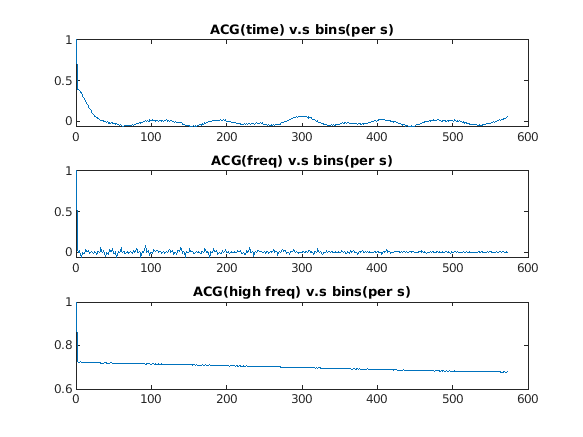


figure,
subplot(3,1,1)
plot(chns_rho);
title('ACG(time) v.s bins(per s)')
%colorbar
subplot(3,1,2)
plot(chf_rho);
title('ACG(freq) v.s bins(per s)')
%colorbar
subplot(3,1,3)
plot(chnsh_rho);
title('ACG(high freq) v.s bins(per s)')

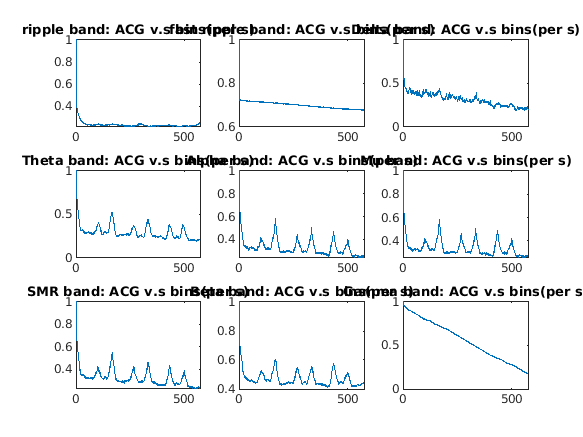

%colorbar

figure,
subplot(3,3,1)
plot(chnsr_rho);
title('ripple band: ACG v.s bins(per s)')
%colorbar
subplot(3,3,2)
plot(chnsfr_rho);
title('fast ripple band: ACG v.s bins(per s)')
%colorbar
subplot(3,3,3)
plot(chnsd_rho);
title('Delta band: ACG v.s bins(per s)')
%colorbar
subplot(3,3,4)
plot(chnsth_rho);
title('Theta band: ACG v.s bins(per s)')
%colorbar
subplot(3,3,5)
plot(chnsa_rho);
title('Alpha band: ACG v.s bins(per s)')
%colorbar
subplot(3,3,6)
%colorbar
plot(chnsm_rho);
title('Mu band: ACG v.s bins(per s)')
%colorbar
subplot(3,3,7)
plot(chnss_rho);
title('SMR band: ACG v.s bins(per s)')
%colorbar
subplot(3,3,8)
plot(chnsb_rho);
title('Beta band: ACG v.s bins(per s)')
%colorbar
subplot(3,3,9)
plot(chnsg_rho);
title('Gamma band: ACG v.s bins(per s)')

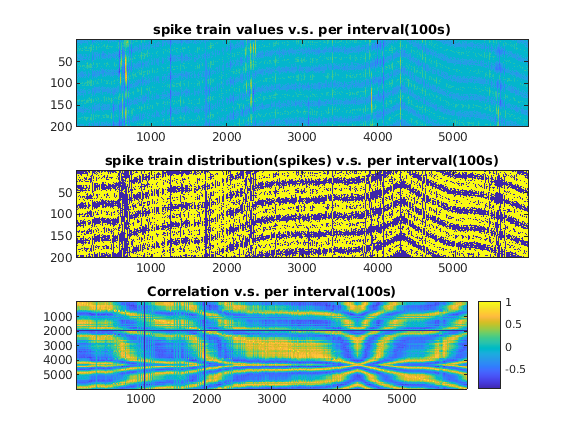

%colorbar
%ylabel(Stim)

% spike train: >5 spikes in one interval
% mark (laptop does not take correct v)
interval = bin/10;% interval: 100ms
if mod(Pnts, interval) > 0
    Nint = floor(Pnts/interval);
else
    Nint = Pnts/interval;
end
Nt_int = zeros(Nint, 1);
s_int = zeros(interval,Nint);
Nr_int = zeros(interval,Nint);
 
for n = 1: Nint
    nn = 2*n - 1;
    if n == Nint
        MEAint_ch = [MEA_ch(interval*(n-1)+1:Pnts); zeros(length(interval) - length(interval*(n-1)+1:Pnts), 1)];
%        MEAint_ch = MEA_ch(interval*(n-1)+1:Pnts);
    else
        MEAint_ch = MEA_ch(interval*(n-1)+1:interval*n);
    end
    Ns_int = length(MEAint_ch(abs(MEAint_ch) > threshold));
    if (Ns_int > 5)
        Nt_int(n) = Ns_int;
        s_int(:,n) = Ns_int.*(abs(MEAint_ch) > threshold);        
        Nr_int(:,n) = MEAint_ch.*(abs(MEAint_ch) > threshold);
    end
end
Ntr = sum(Nt_int);
[chni_rho,chni_p] = corr(Nr_int);
figure,
subplot(3,1,1)
imagesc(Nr_int);
title('spike train values v.s. per interval(100s)')
subplot(3,1,2)
imagesc(s_int==0);
title('spike train distribution(spikes) v.s. per interval(100s)')
subplot(3,1,3)
imagesc(chni_rho);
title('Correlation v.s. per interval(100s)')
colorbar

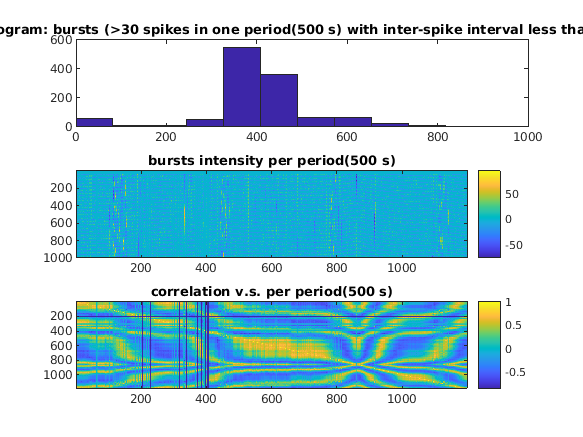


% burst: >30 spikes in one period(500 s with inter-spike interval less than 20 s)
interval2 = round(interval/5);
period = 5*interval;

if mod(Pnts, period) > 0
    Nperiod = floor(Pnts/period) + 1;
else
    Nperiod = Pnts/period;     
end
Nb_per_int2 = zeros(Nperiod,1);
b_per_int2 = zeros(period,Nperiod);

if mod(period, interval2) > 0
    Nint2 = floor(period/interval2) + 1;
else 
    Nint2 = period/interval2;
end

for n = 1: Nperiod
    if n == Nperiod
        MEAper_ch = [MEA_ch(period*(n-1)+1:Pnts);zeros(length(period) - length(period*(n-1)+1:Pnts))];
    else
        MEAper_ch = MEA_ch(period*(n-1)+1:period*n);
    end
    Nb_per = zeros(Nint2,1);
    b_per = zeros(interval2,Nint2);
    for nn = 1: Nint2
        if nn == Nint2
            MEAper_int2_ch = [MEAper_ch(interval2*(nn-1)+1:interval2*nn);zeros(length(interval2) - length(interval2*(nn-1)+1:interval2*nn))];
        else
        	MEAper_int2_ch = MEAper_ch(interval2*(nn-1)+1:interval2*nn);
        end
        Nb_per(nn) = length(MEAper_int2_ch(abs(MEAper_int2_ch) > threshold));
        if nn > 1
            if Nb_per(nn-1)*Nb_per(nn) == 0
                Nb_per(nn) = 0;
            elseif nn < Nint2
                b_per(:, nn) = MEAper_int2_ch.*(abs(MEAper_int2_ch) > threshold);
            else
                b_per(1:interval2, nn) = MEAper_int2_ch.*(abs(MEAper_int2_ch) > threshold);
            end
        end         
    end    
%    MEAper2_int2_ch = MEAper_ch(interval2*Nint2+1:interval2*Nint2+interval2);
    Nb_per_int2(n) = sum(Nb_per); 
    temp = b_per.*(b_per ~= 0);
    b_per_int2(:,n) = temp(:);
end
Nburst = sum(Nb_per_int2);
[chnp_rho,chnp_p] = corr(b_per_int2);
figure,
subplot(3,1,1)
hist(Nb_per_int2);
title('histogram: bursts (>30 spikes in one period(500 s) with inter-spike interval less than 20 s)')
subplot(3,1,2)
imagesc(b_per_int2);
title('bursts intensity per period(500 s)')
colorbar
subplot(3,1,3)
imagesc(chnp_rho);
title('correlation v.s. per period(500 s)')
colorbar

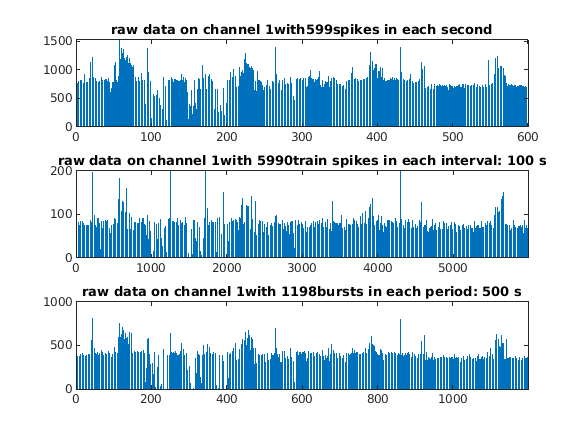

figure,
subplot(3,1,1)
bar(Ns_chn_bin);
title(['raw data on channel ', num2str(ch),'with', num2str(length(Ns_chn_bin)), 'spikes in each second']);
subplot(3,1,2)
bar(Nt_int);
title(['raw data on channel ', num2str(ch),'with ', num2str(length(Nt_int)), 'train spikes in each interval: 100 s']);
subplot(3,1,3)
bar(Nb_per_int2);
title(['raw data on channel ', num2str(ch),'with ', num2str(length(Nb_per_int2)), 'bursts in each period: 500 s']);

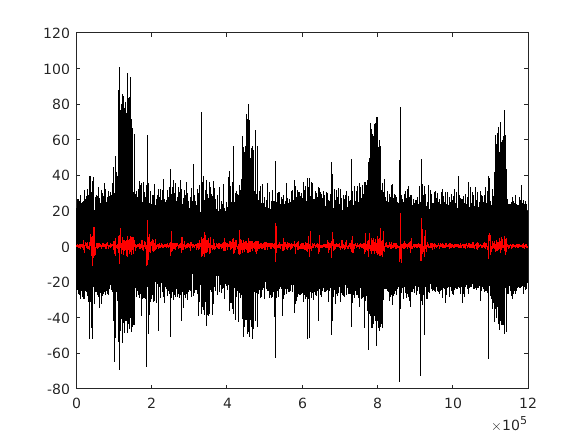

%display(['raw data on channel ', num2str(ch), ' ', 'has ', num2str(Ns),' single spikes,', num2str(Ntr),' spike trains and ', num2str(Nburst),' bursts'])

% preprocess
winlen = bin; %samples per window
b = (1/winlen)*ones(1,winlen);
a = 1;

%filter
MEA_t = filter(b, a, MEAy_ch);
figure
plot(MEAy_ch,'k');
hold on
plot(MEA_t,'r');

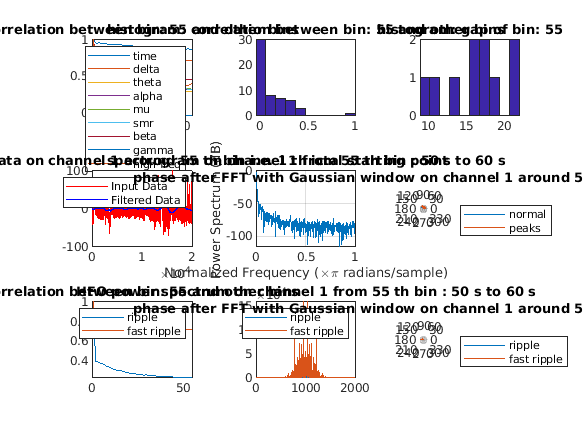

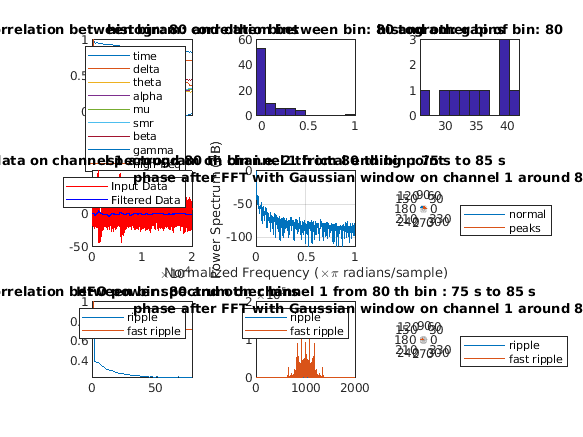

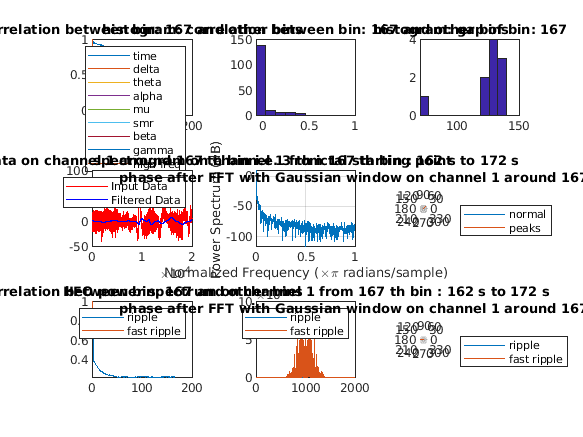

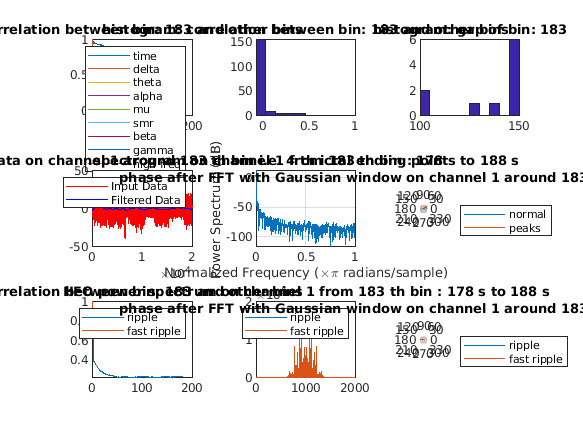

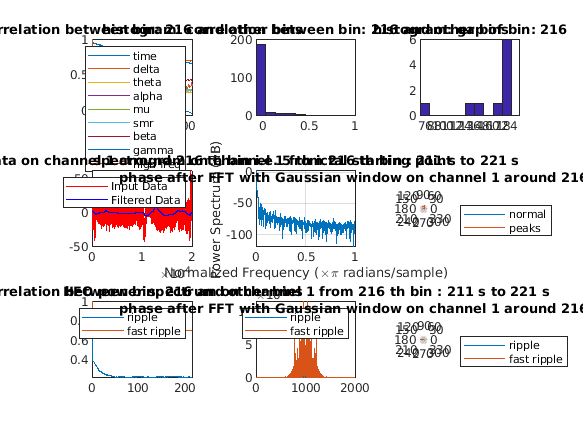

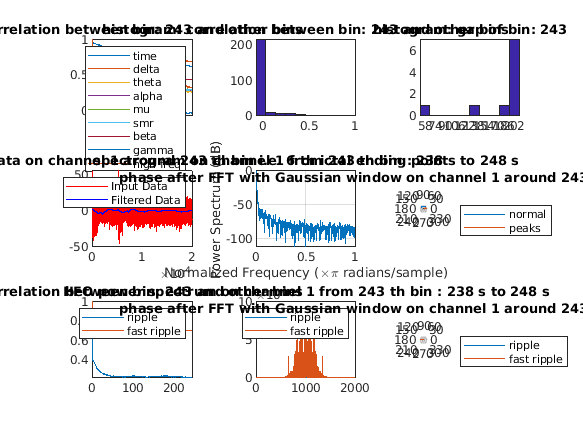

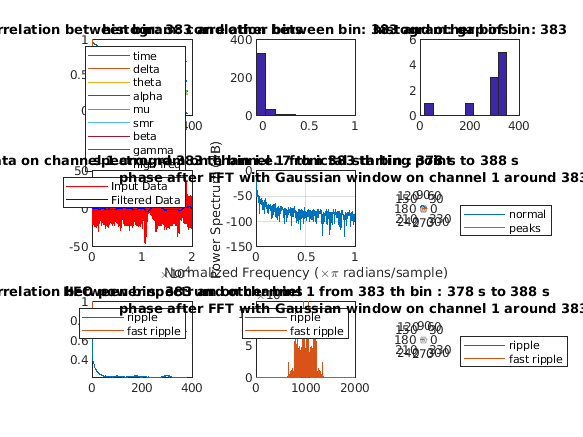

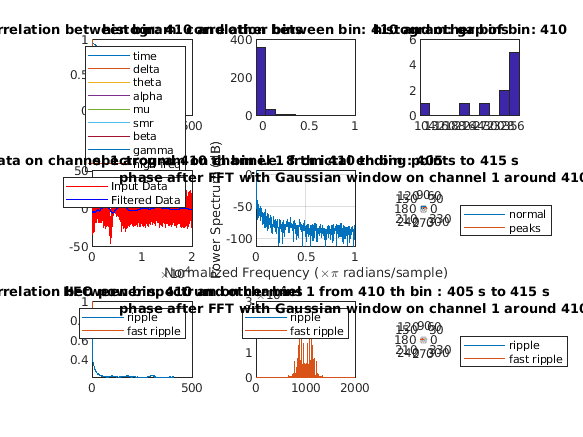

%spikes of ictals (narrow and broad with/without filter)
asym = zeros(length(ictals(:)),1);
dur = zeros(length(ictals(:)),1);
starts = ictals(:,1);
ends = ictals(:,2);
gap = cell(length(ictals(:)));
NBIN = zeros(length(ictals(:)),1);

for n = 1:length(ictals(:))
    if mod(n, 2) == 1
        nbin = floor(starts((n+1)/2));
    else
        nbin = floor(ends(n/2));
    end

    NBIN(n) = nbin;
    
    MEA_ictal_bin = zeros(bin,1);
    
    n_interv = (nbin-5)*bin: (nbin+5)*bin;
    MEA_ictal_bin = MEA_t(bin*(nbin-1)+1:bin*nbin);
    fire_n_interv(:,n)= MEA_ictal_bin;
    
    au = chns_rho(1:nbin);
    aud = chnsd_rho(1:nbin);
    auth = chnsth_rho(1:nbin);
    aua = chnsa_rho(1:nbin);
    aum = chnsm_rho(1:nbin);
    aus = chnss_rho(1:nbin);
    aub = chnsb_rho(1:nbin);
    aug = chnsg_rho(1:nbin);
    auhh = chnsh_rho(1:nbin);
    aur = chnsr_rho(1:nbin);
    aufr = chnsfr_rho(1:nbin);    

    figure,
    subplot(3,3,1)
    plot(au)
    hold on
    plot(aud)
    hold on
    plot(auth)
    hold on
    plot(aua)
    hold on
    plot(aum)
    hold on
    plot(aus)
    hold on
    plot(aub)
    hold on
    plot(aug)
    hold on
    plot(auhh)
   
    
    title(['correlation between bin: ', num2str(nbin), ' and other bins']);
    legend([{'time'},{'delta'},{'theta'},{'alpha'},{'mu'},{'smr'},{'beta'},{'gamma'},{'high freq'}]);
    
    [auh, Bin] = hist(au);
    subplot(3,3,2)
    hist(au)
    title(['histogram: correlation between bin: ', num2str(nbin), ' and other bins']);


    qa1 = quantile(au, 0);
    qa2 = quantile(au, 0.75);
    gapn = au(au <= qa2 & au >= qa1);
    Bini = find(au <= qa2 & au >= qa1);
    [count, center] = hist(gapn);
    for i = 1:length(center)
        B(1+(i-1)*length(Bini(abs(gapn - center(i))< 0.1)):i*length(Bini(abs(gapn - center(i))< 0.1))) = Bini(abs(gapn - center(i))< 0.1);
    end
    gap{n} = hist(B(B > 0));
    subplot(3,3,3)
    hist(gap{n})
    title(['histogram: gap of bin: ', num2str(nbin)]);
    clear B gapn Bini count center
    
    subplot(3,3,4)
    plot(MEAy_ch(n_interv),'r');
    hold on
    plot(MEA_t(n_interv),'b');
    if mod(n,2) == 1
        title(['raw data v.s filtered data on channel ', num2str(ch),' around ', num2str(nbin), ' th bin i.e. ', num2str(n), ' th ictal starting point']);
    else
        title(['raw data v.s filtered data on channel ', num2str(ch),' around ', num2str(nbin), ' th bin i.e. ', num2str(n), ' th ictal ending point']);
    end
    legend('Input Data','Filtered Data')
    
        
    subplot(3,3,5)
    pspectrum(MEA_ictal_bin);
    title(['spectrogram on channel ', num2str(ch),' from ', num2str(nbin), ' th bin : ', num2str(nbin-5),' s to ', num2str(nbin+5), ' s']);

    
    [pks, locs] = findpeaks(MEA_ictal_bin);
    [MAX, MAXI] = max(MEA_ictal_bin);
    [MIN, MINI] = min(MEA_ictal_bin);
    a = MAX - MIN;
    b = pks(length(pks)) - MIN;
    asym(n) = (a - b)/(a + b);
    dur(n) = locs(length(pks)) - MINI;
    
    [phi,w] = phasez(pks);
    A = abs(pks);
   [phi1,w1] = phasez(MEA_ictal_bin);
    A1 = abs(MEA_ictal_bin);
    
    [phih,wh] = phasez(chf_bin_h(nbin,:));
    Ah = abs(chf_bin_h(nbin,:));
   [phir,wr] = phasez(chf_bin_r(nbin,:));
    Ar = abs(chf_bin_r(nbin,:));
   [phifr,wfr] = phasez(chf_bin_fr(nbin,:));
    Afr = abs(chf_bin_fr(nbin,:));
    
    subplot(3,3,6)
    polarplot(w1(1:min(length(A1),length(w1))),A1(1:min(length(A1),length(w1))),w(1:min(length(A),length(w))),A(1:min(length(A),length(w))));
    title(['phase after FFT with Gaussian window on channel ', num2str(ch),' around ', num2str(nbin), ' th bin : ', num2str(nbin-5),' s', num2str(nbin+5), ' s']);
    legend([{'normal'},{'peaks'}]);
    
    subplot(3,3,7)
    plot(aur)
    hold on
    plot(aufr)
    title(['correlation between bin: ', num2str(nbin), ' and other bins']);
    legend([{'ripple'},{'fast ripple'}]);
 
    subplot(3,3,8)
    plot((chf_bin_r(nbin,:).^2)');
    hold on
    plot((chf_bin_fr(nbin,:).^2)');
    title(['HFO power spectrum on channel ', num2str(ch),' from ', num2str(nbin), ' th bin : ', num2str(nbin-5),' s to ', num2str(nbin+5), ' s']);
    legend([{'ripple'},{'fast ripple'}]);
    

    
    subplot(3,3,9)
    polarplot(wr(1:min(length(Ar),length(wr))),Ar(1:min(length(Ar),length(wr))), wfr(1:min(length(Afr),length(wfr))),Afr(1:min(length(Afr),length(wfr))));
    title(['phase after FFT with Gaussian window on channel ', num2str(ch),' around ', num2str(nbin), ' th bin : ', num2str(nbin-5),' s', num2str(nbin+5), ' s']);
    legend([{'ripple'},{'fast ripple'}]);
end

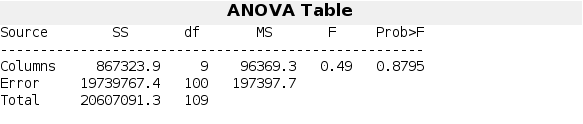

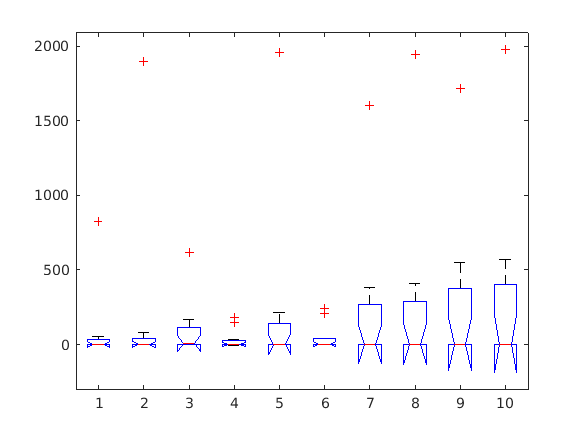

p = 0.8795

tbl = 4×6 cell array
    {'Source' }    {'SS'        }    {'df' }    {'MS'        }    {'F'       }    {'Prob>F'  }
    {'Columns'}    {[8.6732e+05]}    {[  9]}    {[9.6369e+04]}    {[  0.4882]}    {[  0.8795]}
    {'Error'  }    {[1.9740e+07]}    {[100]}    {[1.9740e+05]}    {0×0 double}    {0×0 double}
    {'Total'  }    {[2.0607e+07]}    {[109]}    {0×0 double  }    {0×0 double}    {0×0 double}


stats = struct with fields:
    gnames: [10×2 char]
         n: [11 11 11 11 11 11 11 11 11 11]
    source: 'anova1'
     means: [85.7203 187.3282 88.2381 35.3217 218.1385 49.3024 215.1493 252.4356 257.7328 285.1929]
        df: 100
         s: 444.2946


CORRTF= [chns_rho(NBIN);chnsd_rho(NBIN);chnsth_rho(NBIN);chnsa_rho(NBIN);chnsm_rho(NBIN);chnss_rho(NBIN);chnsb_rho(NBIN);chnsg_rho(NBIN)];

% figure,
% subplot(3,2,1)
% bar(asym);
% title('asymmetry');
% subplot(3,2,2)
% bar(dur);
% title('duration');

for n = 1: length(ictals(:))
    Q3BIN(n) = gap{n}(length(ictals(:)));
    QBINDIST(n) = abs(gap{n}(length(ictals(:)))- gap{n}(1));
    TrSIGMADIST(n) = abs(gap{n}(length(ictals(:)))- NBIN(n));
    MaxIctal(n) = max(abs(fire_n_interv(:, n)),[],1);
    MinIctal(n) = min(abs(fire_n_interv(:, n)),[],1);
    StdIctal(n) = std(abs(fire_n_interv(:, n)),1);
    MeanIctal(n) = mean(abs(fire_n_interv(:, n)),1);
end


CORRTF= CORRTF(1:10);
%MeanCorr = mean(abs(CORRTF),1);
%StdCorr = std(abs(CORRTF),1);
type = ["broad","broad", "broad", "narrow",  "broad","narrow","broad","broad","broad","broad"];
%X = [NBIN; Q3BIN;QBINDIST; TrSIGMADIST;ictal_n_interv;CORRTF];
X1 = [asym'; dur'; NBIN'; Q3BIN;QBINDIST; TrSIGMADIST;MaxIctal;MinIctal;StdIctal;MeanIctal;[-1,-1,-1,1,-1,1,-1,-1,-1,-1]];
%X(isnan(X))= 0;
X1(isnan(X1))= 0;

%%
%[asym_test,dur_test,NBIN_test,Q3BIN_test,QBINDIST_test,TrSIGMADIST_test,fire_n_interv_test,CORRTF_test,MaxIctal_test,MinIctal_test,StdIctal_test,MeanCorr_test,StdCorr_test] = spikes(Pnts, bin, fs, test, MEA_test, MEAy_test, ictals4)
%%
y = [-1,-1,-1,1,-1,1,-1,-1,-1,-1];
%X = [NBIN; Q3BIN;QBINDIST; TrSIGMADIST;ictal_n_interv;CORRTF];
%X1 = [asym'; dur'; NBIN; Q3BIN;QBINDIST; TrSIGMADIST;MaxIctal;MinIctal;StdIctal;MeanCorr;StdCorr;y];
%X(isnan(X))= 0;
%X1(isnan(X1))= 0;

NNBIN = size(NBIN,1);
NQ3BIN = size(Q3BIN,1);
NQBINDIST = size(QBINDIST,1);
NTrSIGMADIST = size(TrSIGMADIST,1);
Nfire_n_interv = size(fire_n_interv,1);
NCORRTF = size(CORRTF,1);
NMaxIctal = size(MaxIctal,1);
NMinIctal  = size(MinIctal ,1);
NStdIctal = size(StdIctal,1);
NMeanIctal  = size(MeanIctal ,1);
NStdIctal  = size(StdIctal ,1);
%type'
group = [0;0;0;1;0;1;0;0;0;0];

R = corr(X1);
[p,tbl,stats] = anova1(X1)

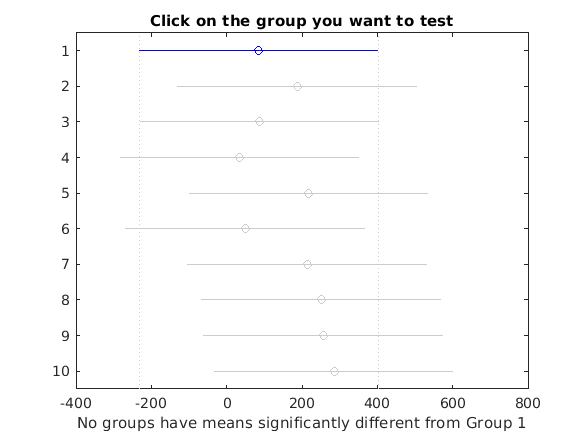

results =     1.0000    2.0000 -737.8030 -101.6079  534.5873    1.0000
    1.0000    3.0000 -638.7130   -2.5178  633.6773    1.0000
    1.0000    4.0000 -585.7966   50.3986  686.5937    1.0000
    1.0000    5.0000 -768.6133 -132.4182  503.7770    1.0000
    1.0000    6.0000 -599.7773   36.4179  672.6130    1.0000
    1.0000    7.0000 -765.6242 -129.4290  506.7661    1.0000
    1.0000    8.0000 -802.9105 -166.7153  469.4798    1.0000
    1.0000    9.0000 -808.2077 -172.0126  464.1826    1.0000
    1.0000   10.0000 -835.6678 -199.4726  436.7225    1.0000
    2.0000    3.0000 -537.1051   99.0900  735.2852    1.0000


means =    85.7203  133.9599
  187.3282  133.9599
   88.2381  133.9599
   35.3217  133.9599
  218.1385  133.9599
   49.3024  133.9599
  215.1493  133.9599
  252.4356  133.9599
  257.7328  133.9599
  285.1929  133.9599


[results,means] = multcompare(stats,'CType','bonferroni')

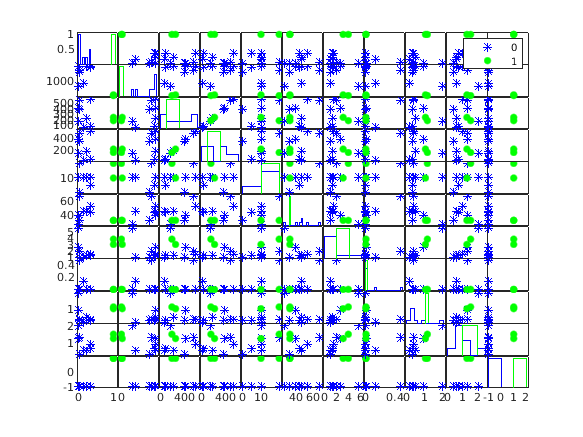

stats =   11×11×2 graphics array.


stats=gplotmatrix(X1',[],group,[],'*.')

Tbtimelm = table(X1(1,:)',X1(2,:)',X1(3,:)',X1(4,:)',X1(5,:)',X1(6,:)',X1(7,:)',X1(8,:)',X1(9,:)',X1(10,:)', group,'VariableNames',{'Asymetry','Duration','spikeBIN','Q3BIN','DIST_Q3', 'DIST_3SIGMA','MAXICTAL','MINICTAL','STDICTAL','MEANICTAL','TYPE'});

lm1_cor1 = fitlm(Tbtimelm,'TYPE~Asymetry/Duration+MEANICTAL*STDICTAL/DIST_3SIGMA+DIST_Q3')

lm1_cor1 = Linear regression model:
    TYPE ~ 1 + Asymetry + DIST_Q3 + Asymetry:Duration + DIST_3SIGMA:STDICTAL + STDICTAL*MEANICTAL + DIST_3SIGMA:STDICTAL:MEANICTAL

Estimated Coefficients:
                                       Estimate          SE         tStat     pValue 
                                      ___________    __________    _______    _______

    (Intercept)                           0.43276       0.39375     1.0991    0.46997
    Asymetry                               1.3799       0.28974     4.7628    0.13175
    DIST_Q3                             -0.015116      0.010761    -1.4047    0.39385
    STDICTAL                              -2.2958         1.917    -1.1977     0.4429
    MEANICTAL                            -0.72481       0.61236    -1.

lm1_cor2 = fitlm(Tbtimelm,'TYPE~Asymetry/Duration+DIST_Q3/DIST_3SIGMA')

lm1_cor2 = Linear regression model:
    TYPE ~ 1 + Asymetry + DIST_Q3 + Asymetry:Duration + DIST_Q3:DIST_3SIGMA

Estimated Coefficients:
                            Estimate          SE         tStat        pValue  
                           ___________    __________    ________    __________

    (Intercept)             -0.0086619      0.027651    -0.31326       0.76673
    Asymetry                    1.0311       0.03944      26.145    1.5297e-06
    DIST_Q3                 -0.0013648     0.0053492    -0.25515       0.80877
    Asymetry:Duration      -0.00051523    4.6281e-05     -11.133    0.00010196
    DIST_Q3:DIST_3SIGMA     1.6852e-05    8.1852e-05     0.20589         0.845


Number of observations: 10, Error degrees of freedom: 5
Root Mean Squared Error: 0.033

Xnew = sort(X1(1:10,:));
ypred = predict(lm1_cor2,Xnew')

ypred =     0.1247
   -0.0083
   -0.0154
   -6.1975
   -0.0100
   -0.0116
   -0.0091
   -0.0091
    0.0219
   -0.0091


%ypred = ypred - 1:10;
ypred(ypred> mean(ypred)) = -1;
ypred(ypred<= mean(ypred)) = 1

ypred =     -1
    -1
    -1
     1
    -1
    -1
    -1
    -1
    -1
    -1


%y = [-1,1,1,-1,-1,1,-1,-1,-1,-1];
y

y =     -1    -1    -1     1    -1     1    -1    -1    -1    -1


ypred == y';
accuracy = sum(ypred == y')/ length(y)

accuracy = 0.9000

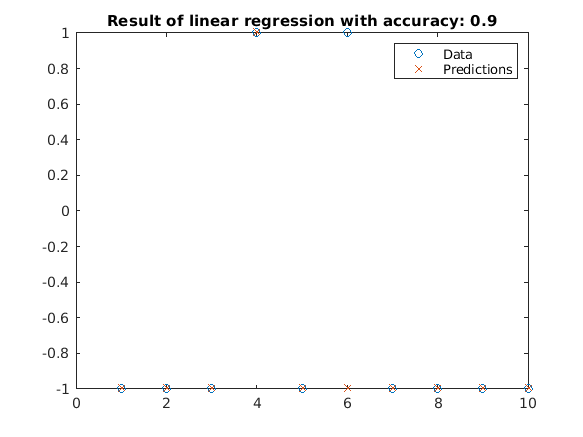

% % Plot the original responses and the predicted responses to see how they differ.
figure,
plot(1:length(y),y,'o',1:length(y),ypred,'x')
legend('Data','Predictions')
title(['Result of linear regression with accuracy: ',num2str(accuracy)]);

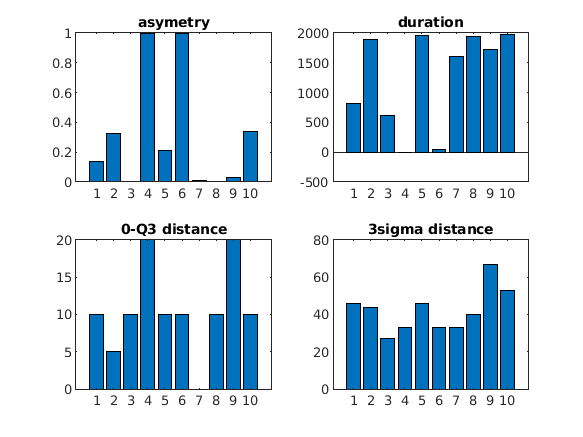


figure,
subplot(2,2,1)     
    bar(asym);
    title('asymetry')
subplot(2,2,2)     
    bar(dur); 
    title('duration')     
subplot(2,2,3)
    bar(QBINDIST(1: size(fire_n_interv,2)));
    title('0-Q3 distance');
subplot(2,2,4)
    bar(TrSIGMADIST(1: size(fire_n_interv,2)));
    title('3sigma distance');

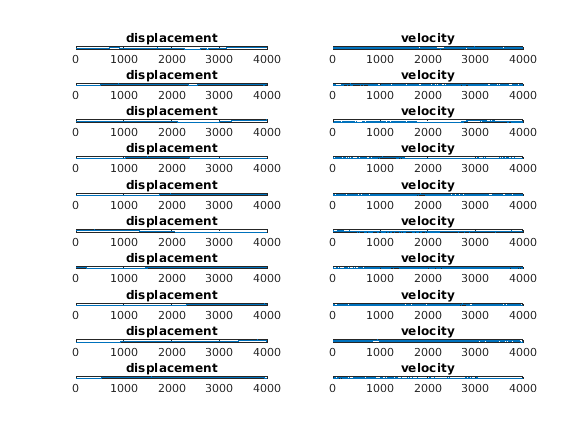

 %   figure,
  %  CORRTF= [chns_rho(NBIN,:),chnsd_rho(NBIN,:),chnsth_rho(NBIN,:),chnsa_rho(NBIN,:),chnsm_rho(NBIN,:),chnss_rho(NBIN,:),chnsb_rho(NBIN,:),chnsg_rho(NBIN,:)];
%    imagesc(CORRTF)
%    title('ACG of the 10 spikes interval on time and frequency domain')
%    colorbar
    
    figure,
    for n = 1:size(fire_n_interv, 2)
        wave = fire_n_interv(:, n);
        N = length(wave);
        if mod(N,2)==1
            v = zeros(2*N-1,1);
            v(1:2:2*N-3) = wave(2:length(wave)) - wave(1:length(wave)-1);
            v(2:2:length(v)-1) = 0.5*v(1:2:length(v)-2)+0.5*v(3:2:length(v));
            s = interp(wave, 2);
        else
            v = zeros(2*N,1);
            v(1:2:2*N-2) = wave(2:length(wave)) - wave(1:length(wave)-1);
            v = [v;v(length(v)-2)];
            v(2:2:length(v)-1) = 0.5*v(1:2:length(v)-2)+0.5*v(3:2:length(v));
            s = interp(wave, 2);
        end
        velocity(:,n) = v;
        displacement(:,n) = s;
        subplot(size(fire_n_interv, 2), 2, 2*n-1)
        plot(s)
        title('displacement')
        subplot(size(fire_n_interv, 2), 2, 2*n)
        plot(v)
        title('velocity')
    end

imftemp =     0.0038    0.0599   -0.0690   -0.0181    0.1351    0.0974    0.0802   -0.1158
   -0.0041    0.0667   -0.0717   -0.0147    0.1355    0.0976    0.0799   -0.1157
    0.0057    0.0610   -0.0741   -0.0113    0.1360    0.0978    0.0795   -0.1156
   -0.0082    0.0494   -0.0762   -0.0079    0.1365    0.0981    0.0792   -0.1155
    0.0010    0.0399   -0.0779   -0.0044    0.1370    0.0983    0.0788   -0.1154
    0.0087    0.0319   -0.0792   -0.0010    0.1375    0.0985    0.0785   -0.1152
    0.0126    0.0226   -0.0801    0.0025    0.1380    0.0988    0.0782   -0.1151
   -0.0123    0.0102   -0.0806    0.0060    0.1386    0.0990    0.0778   -0.1150
    0.0033   -0.0049   -0.0806    0.0095    0.1392    0.0992    0.0775   -0.1149
    0.0106   -0.0199   -0.0802    0.0130    0.1398    0.0995    0.0771   -0.1148


residualtemp =     0.3331
    0.3331
    0.3331
    0.3331
    0.3331
    0.3331
    0.3331
    0.3331
    0.3331
    0.3332


info = struct with fields:
                NumIMF: [8×1 double]
            NumExtrema: [8×1 double]
       NumZerocrossing: [8×1 double]
            NumSifting: [8×1 double]
    MeanEnvelopeEnergy: [8×1 double]
     RelativeTolerance: [8×1 double]


hs =    (2,1)       1.6437
   (4,1)       0.0139
  (94,1)       0.0630
   (1,2)      55.6337
   (2,2)       0.0135
  (48,2)       0.0126
   (1,3)      54.5122
   (2,3)       0.0105
   (1,4)      42.5356
   (2,4)       0.0472
   (1,5)      83.5280
   (1,6)      69.6910
   (1,7)      35.9780
   (1,8)      31.6938
   (1,9)      60.7349
   (1,10)     28.5349
   (1,11)     28.3769
   (1,12)     25.8018
   (1,13)     48.4518
   (1,14)     44.2498
   (1,15)      0.6220
   (1,16)      0.6089
   (1,17)     19.6292
   (1,18)     18.1149
   (1,19)      0.5908
   (1,20)     16.8090
   (1,21)      0.5759
   (1,22)      0.5662
   (1,23)      0.5609
   (1,24)     14.8211
   (1,25)     15.0035
   (1,26)     13.9317
   (1,27)      0.5290
   (1,28)     15.2096
   (1,29)     15.2220
   (1,30)     26.6778
   (1,31)     26.6145
   (1,32)     13.9299
   (1,33)     13.8929
   (1,34)     24.1181
   (1,35)     11.3312
   (1,36)      0.4443
   (1,37)     10.7952
   (1,38)     10.2850
   (1,39)      0.4149
   (1

f =      0
    10
    20
    30
    40
    50
    60
    70
    80
    90


t =          0
    0.0005
    0.0010
    0.0015
    0.0020
    0.0025
    0.0030
    0.0035
    0.0040
    0.0045


imfinsf =    -0.2917   -0.9684   -5.9542  935.1286   14.2498  -30.1620  -12.3376   32.3132
    0.0649   -0.3591   -4.2153  470.8839    7.1406  -15.2670   -5.5912   16.6374
   -0.1154    0.2363   -2.8048   15.1493    3.9299   -8.1592   -1.3357    6.2420
   -0.0979    0.3427   -2.3325   14.2244    3.9394   -8.1752   -1.3471    6.2049
    0.4418    0.3601   -1.6559    5.2232    3.0437   -6.2155   -0.4093    4.0721
    0.3231    0.3762   -1.1833    4.8937    3.0542   -6.2262   -0.4182    4.0496
   -0.6038    0.5636   -0.6111    3.6327    2.6197   -5.2648   -0.0026    3.1239
   -0.2501    0.7465   -0.1335    3.4795    2.6312   -5.2728   -0.0100    3.1078
    0.7018    0.8907    0.4061    3.0638    2.3736   -4.6881    0.2250    2.5883
   -0.0375    0.8447    0.8857    2.9756    2.3858   -4.6944    0.2186    2.5758


imfinse =   108.3735   97.5587    0.1376    0.0630    1.6437    0.1599    0.0374    0.0139
   54.8148   53.6426    0.1232    0.0126    0.8189    0.0853    0.0315    0.0135
   54.7164   53.6753    0.1224    0.0105    0.8234    0.0851    0.0317    0.0135
   40.8999   41.9080    0.1183    0.0472    0.6142    0.0659    0.0300    0.0134
   41.0326   41.8207    0.1185    0.0435    0.6177    0.0658    0.0301    0.0133
   33.6675   35.4267    0.1169    0.0755    0.5080    0.0556    0.0292    0.0133
   33.4866   35.3828    0.1178    0.0711    0.5109    0.0555    0.0293    0.0133
   28.7544   31.1436    0.1172    0.0972    0.4397    0.0489    0.0286    0.0132
   28.9746   31.0653    0.1185    0.0924    0.4423    0.0488    0.0288    0.0132
   25.3454   27.8700    0.1186    0.1139    0.3910    0.0440    0.0283    0.0132


imftemp =     0.0091   -0.0577    0.0516    0.3431   -1.8846    3.5323  -31.7043
    0.0079   -0.0615    0.0444    0.3326   -1.8747    3.5205  -31.6806
   -0.0065   -0.0671    0.0368    0.3219   -1.8647    3.5088  -31.6569
   -0.0042   -0.0728    0.0288    0.3110   -1.8547    3.4970  -31.6332
   -0.0011   -0.0772    0.0205    0.3000   -1.8447    3.4852  -31.6095
    0.0051   -0.0789    0.0117    0.2889   -1.8348    3.4734  -31.5857
   -0.0074   -0.0769    0.0026    0.2775   -1.8248    3.4616  -31.5619
    0.0092   -0.0708   -0.0067    0.2661   -1.8148    3.4498  -31.5381
    0.0154   -0.0609   -0.0163    0.2544   -1.8048    3.4380  -31.5143
    0.0068   -0.0484   -0.0261    0.2426   -1.7948    3.4261  -31.4905


residualtemp =    29.6575
   29.6401
   29.6227
   29.6052
   29.5878
   29.5703
   29.5528
   29.5353
   29.5178
   29.5003


info = struct with fields:
                NumIMF: [7×1 double]
            NumExtrema: [7×1 double]
       NumZerocrossing: [7×1 double]
            NumSifting: [7×1 double]
    MeanEnvelopeEnergy: [7×1 double]
     RelativeTolerance: [7×1 double]


hs =    1.0e+05 *

   (1,1)       2.0695
   (9,1)       0.0001
   (1,2)       1.6473
   (5,2)       0.0003
   (1,3)       1.6457
   (1,4)       1.0437
   (1,5)       1.0421
   (1,6)       1.1966
   (1,7)       0.0132
   (1,8)       0.0115
   (1,9)       0.2985
   (1,10)      0.2724
   (1,11)      0.2727
   (1,12)      0.2524
   (1,13)      0.0367
   (1,14)      0.0326
   (1,15)      0.0328
   (1,16)      0.2226
   (1,17)      0.2228
   (1,18)      0.0268
   (1,19)      0.0269
   (1,20)      0.2010
   (1,21)      0.2011
   (1,22)      0.0227
   (1,23)      0.0228
   (1,24)      0.7281
   (1,25)      0.7278
   (1,26)      0.5450
   (1,27)      0.5446
   (1,28)      0.6794
   (1,29)      0.6790
   (1,30)      0.6580
   (1,31)      0.5095
   (1,32)      0.4944
   (1,33)      0.5059
   (1,34)      0.6314
   (1,35)      0.1668
   (1,36)      0.1620
   (1,37)      0.1621
   (1,38)      0.0250
   (1,39)      0.0250
   (1,40)      0.1535
   (1,41)      0.1536
   (1,42)      0.0233
   (1,43)    

f =      0
    10
    20
    30
    40
    50
    60
    70
    80
    90


t =          0
    0.0005
    0.0010
    0.0015
    0.0020
    0.0025
    0.0030
    0.0035
    0.0040
    0.0045


imfinsf = imfinsf(:,:,1) =

   -0.2917   -0.9684   -5.9542  935.1286   14.2498  -30.1620  -12.3376   32.3132
    0.0649   -0.3591   -4.2153  470.8839    7.1406  -15.2670   -5.5912   16.6374
   -0.1154    0.2363   -2.8048   15.1493    3.9299   -8.1592   -1.3357    6.2420
   -0.0979    0.3427   -2.3325   14.2244    3.9394   -8.1752   -1.3471    6.2049
    0.4418    0.3601   -1.6559    5.2232    3.0437   -6.2155   -0.4093    4.0721
    0.3231    0.3762   -1.1833    4.8937    3.0542   -6.2262   -0.4182    4.0496
   -0.6038    0.5636   -0.6111    3.6327    2.6197   -5.2648   -0.0026    3.1239
   -0.2501    0.7465   -0.1335    3.4795    2.6312   -5.2728   -0.0100    3.1078
    0.7018    0.8907    0.4061    3.0638    2.3736   -4.6881    0.2250    2.5883
   -0.0375    0.8447    0.8857    2.9756    2.3858   -4.6944    0.2186    2.5758
   -0.6900    0.7425    1.4082    2.7866    2.2167   -4.2952    0.3697    2.2422
   -0.3545    0.5728    1.8870    2.7282    2.2296   -4.3002    0.3640    2.2320


imfinse = imfinse(:,:,1) =

  108.3735   97.5587    0.1376    0.0630    1.6437    0.1599    0.0374    0.0139
   54.8148   53.6426    0.1232    0.0126    0.8189    0.0853    0.0315    0.0135
   54.7164   53.6753    0.1224    0.0105    0.8234    0.0851    0.0317    0.0135
   40.8999   41.9080    0.1183    0.0472    0.6142    0.0659    0.0300    0.0134
   41.0326   41.8207    0.1185    0.0435    0.6177    0.0658    0.0301    0.0133
   33.6675   35.4267    0.1169    0.0755    0.5080    0.0556    0.0292    0.0133
   33.4866   35.3828    0.1178    0.0711    0.5109    0.0555    0.0293    0.0133
   28.7544   31.1436    0.1172    0.0972    0.4397    0.0489    0.0286    0.0132
   28.9746   31.0653    0.1185    0.0924    0.4423    0.0488    0.0288    0.0132
   25.3454   27.8700    0.1186    0.1139    0.3910    0.0440    0.0283    0.0132
   25.3020   27.7133    0.1200    0.1088    0.3933    0.0440    0.0284    0.0132
   22.6906   25.1595    0.1204    0.1267    0.3540    0.0404    0.0280    0.0131


imftemp =     0.0016    0.0083    0.2023   -0.7360    0.1076    0.3672   -0.2039    0.1368
    0.0086    0.0069    0.2079   -0.7383    0.1080    0.3664   -0.2041    0.1367
    0.0053    0.0028    0.2146   -0.7405    0.1084    0.3656   -0.2042    0.1365
   -0.0052   -0.0033    0.2221   -0.7425    0.1089    0.3648   -0.2043    0.1364
   -0.0071   -0.0100    0.2303   -0.7444    0.1092    0.3640   -0.2044    0.1363
    0.0065   -0.0156    0.2391   -0.7461    0.1096    0.3632   -0.2045    0.1362
    0.0006   -0.0181    0.2482   -0.7476    0.1100    0.3624   -0.2046    0.1361
   -0.0055   -0.0163    0.2572   -0.7489    0.1103    0.3615   -0.2047    0.1360
   -0.0020   -0.0091    0.2660   -0.7499    0.1106    0.3607   -0.2048    0.1359
    0.0065    0.0016    0.2744   -0.7507    0.1110    0.3599   -0.2049    0.1358


residualtemp =     0.0464
    0.0464
    0.0465
    0.0466
    0.0466
    0.0467
    0.0468
    0.0468
    0.0469
    0.0470


info = struct with fields:
                NumIMF: [8×1 double]
            NumExtrema: [8×1 double]
       NumZerocrossing: [8×1 double]
            NumSifting: [8×1 double]
    MeanEnvelopeEnergy: [8×1 double]
     RelativeTolerance: [8×1 double]


hs =    (1,1)     196.2203
   (3,1)       1.0558
   (5,1)      21.3020
   (1,2)      92.7568
   (2,2)       0.5029
   (3,2)       6.0220
   (1,3)      14.0415
   (2,3)       6.2784
   (1,4)      12.5105
   (2,4)       3.3683
   (1,5)      66.4167
   (2,5)       3.5108
   (1,6)      53.1234
   (2,6)       2.2448
   (1,7)      10.4910
   (2,7)       2.3356
   (1,8)       0.2576
   (2,8)       1.6362
   (1,9)      34.9199
   (2,9)       1.6973
   (1,10)      0.2271
   (2,10)      1.2646
   (1,11)      0.5016
   (2,11)      1.3063
   (1,12)     25.8234
   (2,12)      1.0213
   (1,13)     33.6901
   (2,13)      1.0495
   (1,14)      7.9338
   (2,14)      0.8551
   (1,15)      7.7285
   (2,15)      0.8734
   (1,16)      7.3846
   (2,16)      0.7386
   (1,17)     27.0606
   (2,17)      0.7493
   (1,18)     18.1854
   (2,18)      0.6559
   (1,19)     18.2567
   (2,19)      0.6608
   (1,20)     16.4338
   (2,20)      0.5972
   (1,21)      0.4138
   (2,21)      0.5974
   (1,22)      0.4036
   (2

f =      0
    10
    20
    30
    40
    50
    60
    70
    80
    90


t =          0
    0.0005
    0.0010
    0.0015
    0.0020
    0.0025
    0.0030
    0.0035
    0.0040
    0.0045


imfinsf = imfinsf(:,:,1) =

   -0.2917   -0.9684   -5.9542  935.1286   14.2498  -30.1620  -12.3376   32.3132
    0.0649   -0.3591   -4.2153  470.8839    7.1406  -15.2670   -5.5912   16.6374
   -0.1154    0.2363   -2.8048   15.1493    3.9299   -8.1592   -1.3357    6.2420
   -0.0979    0.3427   -2.3325   14.2244    3.9394   -8.1752   -1.3471    6.2049
    0.4418    0.3601   -1.6559    5.2232    3.0437   -6.2155   -0.4093    4.0721
    0.3231    0.3762   -1.1833    4.8937    3.0542   -6.2262   -0.4182    4.0496
   -0.6038    0.5636   -0.6111    3.6327    2.6197   -5.2648   -0.0026    3.1239
   -0.2501    0.7465   -0.1335    3.4795    2.6312   -5.2728   -0.0100    3.1078
    0.7018    0.8907    0.4061    3.0638    2.3736   -4.6881    0.2250    2.5883
   -0.0375    0.8447    0.8857    2.9756    2.3858   -4.6944    0.2186    2.5758
   -0.6900    0.7425    1.4082    2.7866    2.2167   -4.2952    0.3697    2.2422
   -0.3545    0.5728    1.8870    2.7282    2.2296   -4.3002    0.3640    2.2320


imfinse = imfinse(:,:,1) =

  108.3735   97.5587    0.1376    0.0630    1.6437    0.1599    0.0374    0.0139
   54.8148   53.6426    0.1232    0.0126    0.8189    0.0853    0.0315    0.0135
   54.7164   53.6753    0.1224    0.0105    0.8234    0.0851    0.0317    0.0135
   40.8999   41.9080    0.1183    0.0472    0.6142    0.0659    0.0300    0.0134
   41.0326   41.8207    0.1185    0.0435    0.6177    0.0658    0.0301    0.0133
   33.6675   35.4267    0.1169    0.0755    0.5080    0.0556    0.0292    0.0133
   33.4866   35.3828    0.1178    0.0711    0.5109    0.0555    0.0293    0.0133
   28.7544   31.1436    0.1172    0.0972    0.4397    0.0489    0.0286    0.0132
   28.9746   31.0653    0.1185    0.0924    0.4423    0.0488    0.0288    0.0132
   25.3454   27.8700    0.1186    0.1139    0.3910    0.0440    0.0283    0.0132
   25.3020   27.7133    0.1200    0.1088    0.3933    0.0440    0.0284    0.0132
   22.6906   25.1595    0.1204    0.1267    0.3540    0.0404    0.0280    0.0131


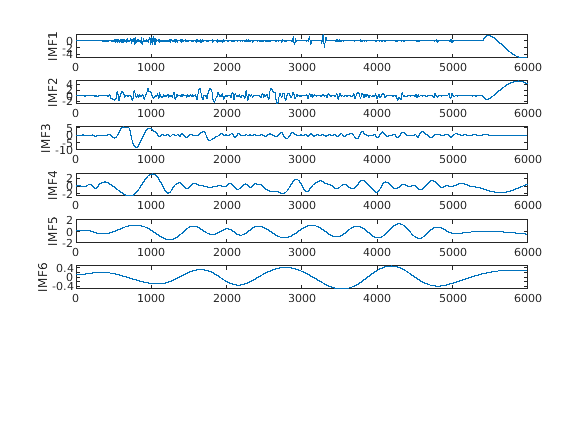

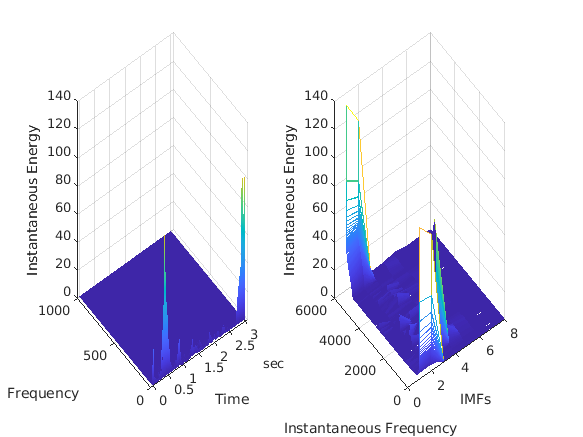

imftemp =     0.0136    0.0063    0.0179    0.4434   -0.0764   -0.1668   -0.2188
   -0.0109    0.0028    0.0043    0.4307   -0.0788   -0.1668   -0.2185
   -0.0195   -0.0010   -0.0109    0.4150   -0.0812   -0.1668   -0.2182
   -0.0184   -0.0032   -0.0271    0.3966   -0.0835   -0.1667   -0.2179
   -0.0080   -0.0034   -0.0435    0.3755   -0.0857   -0.1667   -0.2176
    0.0159   -0.0016   -0.0597    0.3521   -0.0878   -0.1666   -0.2173
   -0.0006    0.0012   -0.0749    0.3263   -0.0899   -0.1666   -0.2170
   -0.0152    0.0025   -0.0889    0.2985   -0.0919   -0.1665   -0.2167
   -0.0011    0.0002   -0.1013    0.2686   -0.0939   -0.1664   -0.2163
    0.0142   -0.0046   -0.1121    0.2370   -0.0958   -0.1662   -0.2160


residualtemp =     0.2483
    0.2484
    0.2484
    0.2484
    0.2484
    0.2484
    0.2484
    0.2484
    0.2484
    0.2484


info = struct with fields:
                NumIMF: [7×1 double]
            NumExtrema: [7×1 double]
       NumZerocrossing: [7×1 double]
            NumSifting: [7×1 double]
    MeanEnvelopeEnergy: [7×1 double]
     RelativeTolerance: [7×1 double]


hs =    (1,1)      14.3841
  (14,1)       0.6349
   (1,2)       5.8398
   (2,2)       0.1007
   (8,2)       0.2571
   (1,3)       5.8794
   (2,3)       0.1131
   (6,3)       0.2273
   (1,4)       6.4098
   (2,4)       0.0700
   (6,4)       0.1642
   (1,5)       2.6633
   (3,5)       0.0766
   (6,5)       0.1439
   (1,6)       1.8681
   (3,6)       0.0553
   (6,6)       0.1262
   (1,7)       0.2946
   (3,7)       0.0590
   (6,7)       0.1120
   (1,8)       2.5930
   (3,8)       0.0457
   (6,8)       0.1118
   (1,9)       4.0201
   (3,9)       0.0477
   (6,9)       0.1025
   (1,10)      3.2748
   (3,10)      0.0387
   (6,10)      0.1116
   (1,11)      2.2109
   (3,11)      0.0399
   (5,11)      0.1065
   (1,12)      1.8856
   (3,12)      0.0338
   (5,12)      0.1216
   (1,13)      1.1867
   (3,13)      0.0345
   (4,13)      0.1202
   (1,14)      1.0345
   (3,14)      0.0304
   (4,14)      0.1393
   (1,15)      0.2944
   (3,15)      0.0309
   (4,15)      0.1412
   (1,16)      0.9164
   (3

f =      0
    10
    20
    30
    40
    50
    60
    70
    80
    90


t =          0
    0.0005
    0.0010
    0.0015
    0.0020
    0.0025
    0.0030
    0.0035
    0.0040
    0.0045


imfinsf = imfinsf(:,:,1) =

   -0.2917   -0.9684   -5.9542  935.1286   14.2498  -30.1620  -12.3376   32.3132
    0.0649   -0.3591   -4.2153  470.8839    7.1406  -15.2670   -5.5912   16.6374
   -0.1154    0.2363   -2.8048   15.1493    3.9299   -8.1592   -1.3357    6.2420
   -0.0979    0.3427   -2.3325   14.2244    3.9394   -8.1752   -1.3471    6.2049
    0.4418    0.3601   -1.6559    5.2232    3.0437   -6.2155   -0.4093    4.0721
    0.3231    0.3762   -1.1833    4.8937    3.0542   -6.2262   -0.4182    4.0496
   -0.6038    0.5636   -0.6111    3.6327    2.6197   -5.2648   -0.0026    3.1239
   -0.2501    0.7465   -0.1335    3.4795    2.6312   -5.2728   -0.0100    3.1078
    0.7018    0.8907    0.4061    3.0638    2.3736   -4.6881    0.2250    2.5883
   -0.0375    0.8447    0.8857    2.9756    2.3858   -4.6944    0.2186    2.5758
   -0.6900    0.7425    1.4082    2.7866    2.2167   -4.2952    0.3697    2.2422
   -0.3545    0.5728    1.8870    2.7282    2.2296   -4.3002    0.3640    2.2320


imfinse = imfinse(:,:,1) =

  108.3735   97.5587    0.1376    0.0630    1.6437    0.1599    0.0374    0.0139
   54.8148   53.6426    0.1232    0.0126    0.8189    0.0853    0.0315    0.0135
   54.7164   53.6753    0.1224    0.0105    0.8234    0.0851    0.0317    0.0135
   40.8999   41.9080    0.1183    0.0472    0.6142    0.0659    0.0300    0.0134
   41.0326   41.8207    0.1185    0.0435    0.6177    0.0658    0.0301    0.0133
   33.6675   35.4267    0.1169    0.0755    0.5080    0.0556    0.0292    0.0133
   33.4866   35.3828    0.1178    0.0711    0.5109    0.0555    0.0293    0.0133
   28.7544   31.1436    0.1172    0.0972    0.4397    0.0489    0.0286    0.0132
   28.9746   31.0653    0.1185    0.0924    0.4423    0.0488    0.0288    0.0132
   25.3454   27.8700    0.1186    0.1139    0.3910    0.0440    0.0283    0.0132
   25.3020   27.7133    0.1200    0.1088    0.3933    0.0440    0.0284    0.0132
   22.6906   25.1595    0.1204    0.1267    0.3540    0.0404    0.0280    0.0131


imftemp =    -0.0038    0.0162    0.0078    0.1259   -1.1782   -0.2587   -0.3710
    0.0049    0.0118    0.0065    0.1141   -1.1777   -0.2590   -0.3706
    0.0081    0.0072    0.0047    0.1015   -1.1772   -0.2593   -0.3702
    0.0050    0.0037    0.0025    0.0883   -1.1767   -0.2596   -0.3698
   -0.0068    0.0020    0.0001    0.0745   -1.1761   -0.2600   -0.3694
    0.0056    0.0020   -0.0023    0.0604   -1.1754   -0.2603   -0.3690
    0.0031    0.0017   -0.0046    0.0459   -1.1747   -0.2606   -0.3686
   -0.0027    0.0006   -0.0067    0.0312   -1.1740   -0.2609   -0.3682
    0.0021   -0.0008   -0.0084    0.0165   -1.1733   -0.2612   -0.3677
   -0.0025    0.0003   -0.0096    0.0018   -1.1725   -0.2615   -0.3673


residualtemp =     0.0915
    0.0915
    0.0916
    0.0916
    0.0916
    0.0916
    0.0916
    0.0916
    0.0916
    0.0917


info = struct with fields:
                NumIMF: [7×1 double]
            NumExtrema: [7×1 double]
       NumZerocrossing: [7×1 double]
            NumSifting: [7×1 double]
    MeanEnvelopeEnergy: [7×1 double]
     RelativeTolerance: [7×1 double]


hs =    (3,1)       0.1428
   (6,1)      19.9568
   (2,2)       0.1395
   (3,2)       8.1306
   (1,3)       1.2616
   (2,3)       8.2222
   (1,4)      17.9677
   (2,4)       5.6050
   (1,5)       0.8352
   (2,5)       5.6634
   (1,6)       0.6201
   (2,6)       4.4010
   (1,7)      17.0073
   (2,7)       4.2330
   (1,8)      16.6329
   (2,8)       3.5006
   (1,9)       4.2309
   (1,10)     41.9888
   (1,11)     26.5032
   (1,12)     24.1689
   (1,13)     17.6338
   (2,13)      0.2287
   (1,14)     17.2083
   (2,14)      0.1878
   (1,15)      2.7267
   (2,15)      0.1898
   (1,16)     20.6122
   (2,16)      0.1570
   (1,17)     34.4446
   (2,17)      0.1579
   (1,18)     33.0265
   (2,18)      0.1312
   (1,19)     32.7154
   (2,19)      0.1313
   (1,20)     18.1261
   (2,20)      0.1095
   (1,21)      2.2120
   (2,21)      0.1089
   (1,22)     14.9401
   (2,22)      0.0910
   (1,23)     14.8293
   (3,23)      0.0898
   (1,24)     14.5159
   (3,24)      0.0753
   (1,25)      1.9984
   (3

f =      0
    10
    20
    30
    40
    50
    60
    70
    80
    90


t =          0
    0.0005
    0.0010
    0.0015
    0.0020
    0.0025
    0.0030
    0.0035
    0.0040
    0.0045


imfinsf = imfinsf(:,:,1) =

   -0.2917   -0.9684   -5.9542  935.1286   14.2498  -30.1620  -12.3376   32.3132
    0.0649   -0.3591   -4.2153  470.8839    7.1406  -15.2670   -5.5912   16.6374
   -0.1154    0.2363   -2.8048   15.1493    3.9299   -8.1592   -1.3357    6.2420
   -0.0979    0.3427   -2.3325   14.2244    3.9394   -8.1752   -1.3471    6.2049
    0.4418    0.3601   -1.6559    5.2232    3.0437   -6.2155   -0.4093    4.0721
    0.3231    0.3762   -1.1833    4.8937    3.0542   -6.2262   -0.4182    4.0496
   -0.6038    0.5636   -0.6111    3.6327    2.6197   -5.2648   -0.0026    3.1239
   -0.2501    0.7465   -0.1335    3.4795    2.6312   -5.2728   -0.0100    3.1078
    0.7018    0.8907    0.4061    3.0638    2.3736   -4.6881    0.2250    2.5883
   -0.0375    0.8447    0.8857    2.9756    2.3858   -4.6944    0.2186    2.5758
   -0.6900    0.7425    1.4082    2.7866    2.2167   -4.2952    0.3697    2.2422
   -0.3545    0.5728    1.8870    2.7282    2.2296   -4.3002    0.3640    2.2320


imfinse = imfinse(:,:,1) =

  108.3735   97.5587    0.1376    0.0630    1.6437    0.1599    0.0374    0.0139
   54.8148   53.6426    0.1232    0.0126    0.8189    0.0853    0.0315    0.0135
   54.7164   53.6753    0.1224    0.0105    0.8234    0.0851    0.0317    0.0135
   40.8999   41.9080    0.1183    0.0472    0.6142    0.0659    0.0300    0.0134
   41.0326   41.8207    0.1185    0.0435    0.6177    0.0658    0.0301    0.0133
   33.6675   35.4267    0.1169    0.0755    0.5080    0.0556    0.0292    0.0133
   33.4866   35.3828    0.1178    0.0711    0.5109    0.0555    0.0293    0.0133
   28.7544   31.1436    0.1172    0.0972    0.4397    0.0489    0.0286    0.0132
   28.9746   31.0653    0.1185    0.0924    0.4423    0.0488    0.0288    0.0132
   25.3454   27.8700    0.1186    0.1139    0.3910    0.0440    0.0283    0.0132
   25.3020   27.7133    0.1200    0.1088    0.3933    0.0440    0.0284    0.0132
   22.6906   25.1595    0.1204    0.1267    0.3540    0.0404    0.0280    0.0131


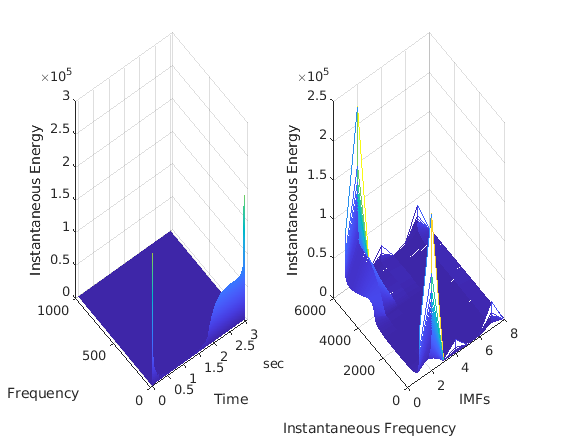

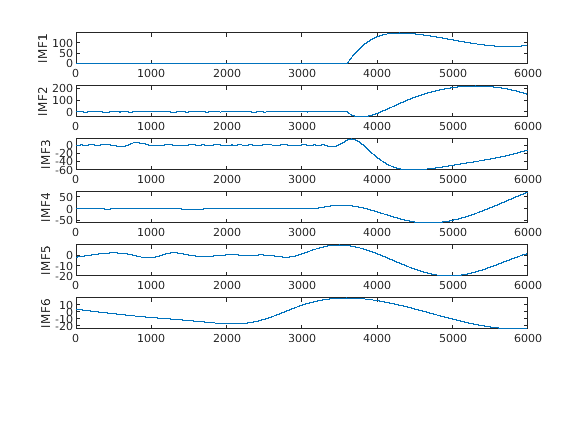

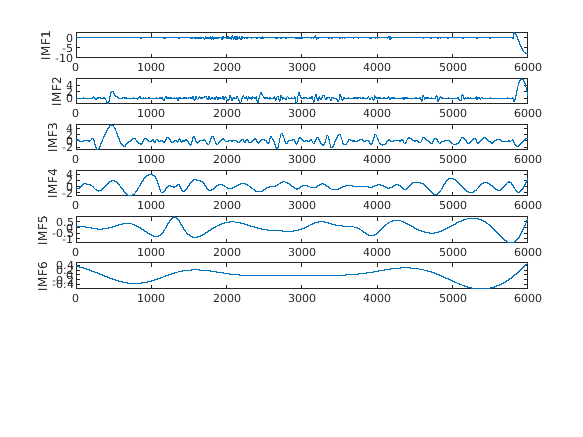

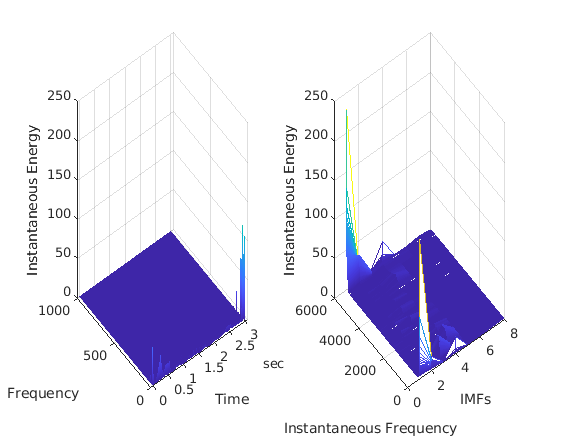

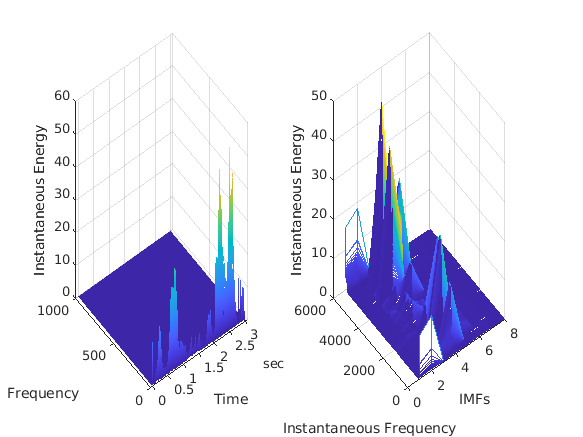

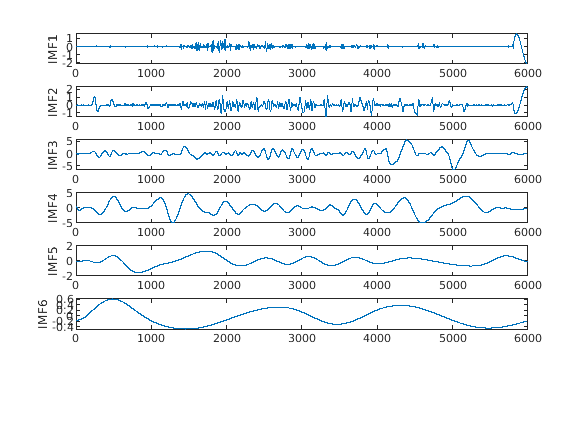

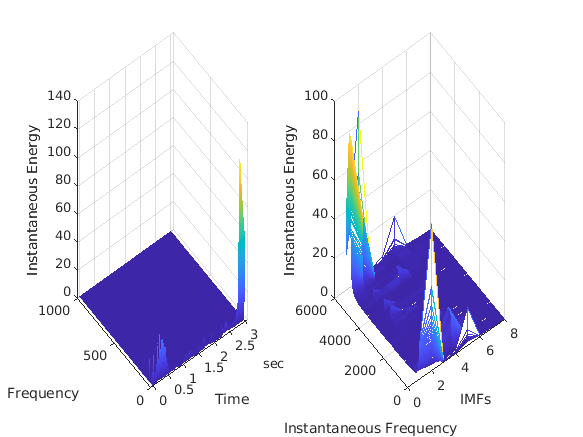

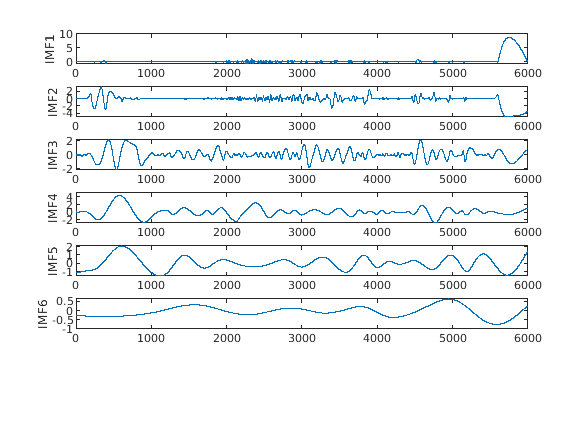

%manovacluster(ictal_n_interv)
% legend('Input Data','Filtered Data')
% 
% plot(interval,MEAy_ch(bin*(n-1)+1:bin*(n-1)+1+length(interval)-1),'r');
% hold on
% plot(interval,MEA_t(bin*(n-1)+1:bin*(n-1)+1+length(interval)-1),'b');
% title(['raw data v.s filtered data on channel', num2str(ch),' ', num2str(n_interv), 'th ictal interval : ', num2str(n),' s to ', num2str(n_end), ' s']);
% legend('Input Data','Filtered Data')
% ictal_n_interv = ictal_n_interv(:, 1:2:size(ictal_n_interv,2));
type = ["interictal","ictal", "ictal", "interictal",  "interictal"];
group = [0,1,1,0,0];
y = [-1,1,1,-1,-1];
%[Asym, Dur, ypred, lml_cor3] = ictalclassify(ictal_n_interv, fs, asym, dur, type, group, y, ch)

% ictal, inter-ictal 
ictal_n_interv = zeros(60000,5);
for i = 1:size(ictals, 1)
    ictal_n_interv(1:length((floor(ictals(i,1))-1)*bin+1: (floor(ictals(i,2))+1)*bin),i) = MEA_t((floor(ictals(i,1))-1)*bin+1: (floor(ictals(i,2))+1)*bin);
end
EEG = ictal_n_interv(1:10:size(ictal_n_interv, 1), :);
%L = size(ictal_n_interv, 2);
%seglen = bin;
%M = ceil(size(ictal_n_interv, 1)/bin);
%a = 0.1;
%FF = RD_STFT(EEG, fs, M, L, seglen, a);%overlap 0.5
[yupper,ylower] = envelope(EEG);
[M, N] = size(EEG); 
SE = zeros(M, N);
SEH = SE;
for i = 1:N
    %empirical mode decompose 
    figure(2*i-1),
    title('IMF')
   [imftemp,residualtemp,info] = emd(EEG(:,i),'MaxNumIMF',10, 'Display',0)%hide table
   imf(1:size(imftemp,1), 1:size(imftemp,2), i) = imftemp;
   residualtemp(1:size(residualtemp,1), 1:size(residualtemp,2), i) = residualtemp;   
%   figure, have to plot by mysef somehow
%   plot(imf)
    subplot(size(imftemp,2), 1, 1)
    plot(imf(:,1,i))
    ylabel('IMF1')
    subplot(size(imftemp,2), 1, 2)
    plot(imf(:,2,i)) 
    ylabel('IMF2')
    subplot(size(imftemp,2), 1, 3)
    plot(imf(:,3,i))
    ylabel('IMF3')
    subplot(size(imftemp,2), 1, 4)
    plot(imf(:,4,i))
    ylabel('IMF4')
    subplot(size(imftemp,2), 1, 5)
    plot(imf(:,5,i))
    ylabel('IMF5')
    subplot(size(imftemp,2), 1, 6)
    plot(imf(:,6,i))
    ylabel('IMF6')
    
   figure(2*i),
   [hs,f,t,imfinsf(1:size(imf,1),1:size(imf,2,i),i),imfinse(1:size(imf,1),1:size(imf,2,i),i)] = hht(imf(:, :, i), fs)
   subplot(1, 2, 1)
   mesh(seconds(t),f,hs,'EdgeColor','none','FaceColor','interp')
   xlabel('Time')
   ylabel('Frequency')
   zlabel('Instantaneous Energy')
   
   subplot(1, 2, 2)
   mesh(imfinse(1:size(imf,1),1:size(imf,2,i),i),imfinse(1:size(imf,1),1:size(imf,2,i),i))
   xlabel('IMFs')   
   ylabel('Instantaneous Frequency')
   zlabel('Instantaneous Energy')
   
   mdl = fit([1: size(yupper,1)]', 0.5*(yupper(:,i)+ylower(:,i)), 'poly3', 'Normalize','on', 'Robust','Bisquare'); 
   h(:,i) = EEG(:, i)- mdl(1:M);
   k = 1;
   hk(:,k) = abs(h(:,i) - mean(h(:,i) , 1));
%   [~,~,~,Hk,~]= hht(hk(:,k), fs) 
   SD = abs(hk(:,k) - abs(hk(:,k)  - mean(hk(:,k) , 1))).^2./abs(hk(:,k) - mean(hk(:,k) , 1)).^2;   
   while  sum(SD > mean(SD))>0.001*i*M & k < size(imf,2) -1
       hk(:,k+1)  = abs(hk(:,k) - mean(hk(:,k) , 1));
       dif= imf(:,k)-hk(:,k+1);
       SD = SD + abs(hk(:,k) - abs(hk(:,k+1)  - mean(hk(:,k+1), 1))).^2./abs(hk(:,k+1) - mean(hk(:,k+1) , 1)).^2;          
       k = k+1;
   end
   if k >1       
       SE(:,i) = sum(hk./repmat(sum(hk,2),[1, size(hk,2)]).*log(hk./repmat(sum(hk,2),[1,size(hk,2)])),2);
%       SEH(:,i) = sum(Hk./repmat(sum(Hk,2),[1, size(Hk,2)]).*log(Hk./repmat(sum(Hk,2),[1,size(Hk,2)])),2);
   else
       SE(:,i) = hk/sum(hk).*log(hk/sum(hk))+(1-hk/sum(hk)).*log(1-hk/sum(hk));
%       SEH(:,i) = Hk/sum(Hk).*log(Hk/sum(Hk))+(1-Hk/sum(Hk)).*log(1-Hk/sum(Hk));
   end
   clear hk Hk SD mdl hs
end

difE = SE-mean(imfinse,2);

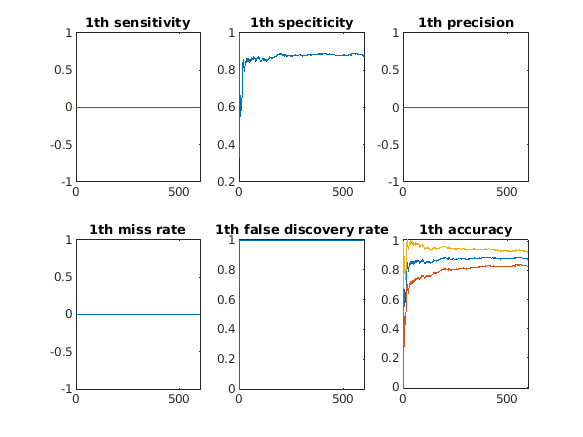

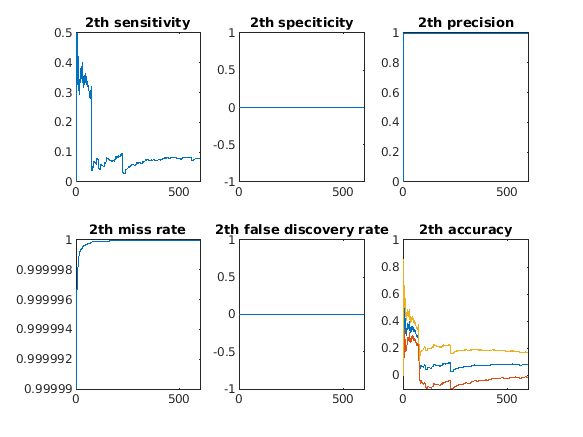

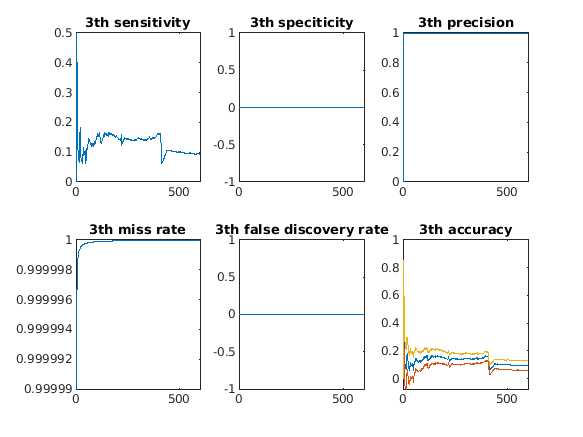

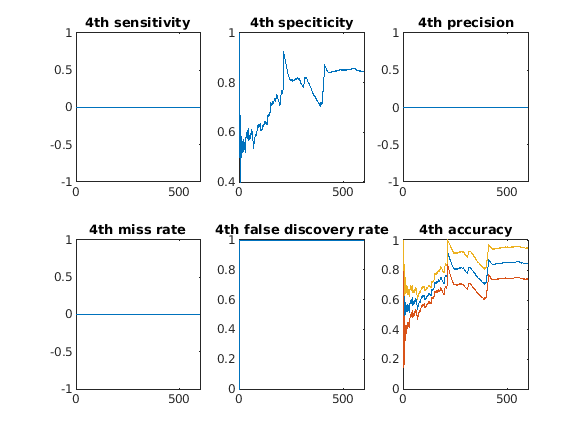

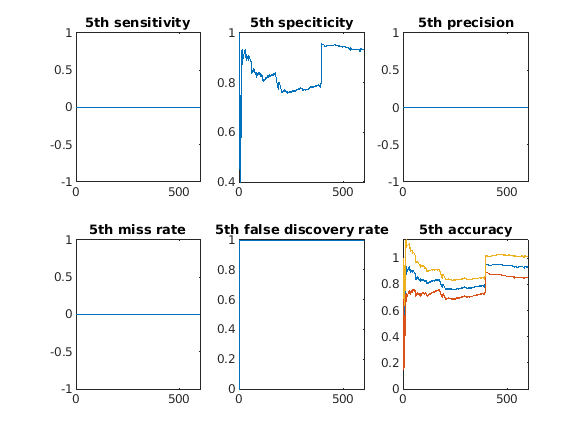

%hmmm of ictal type 
% logistic regression with regulation
eta0 = 0.1;
%threshold1 = 80;
%threshold2 = 120;
%fn = 0:bin-1;
%f = 1.0*double(fn)/double(bin-1);
%t = -0.5:1/bin:0.5;  % Time vector 
%L = length(t)-1;      % Signal length
%X = 1/(4*sqrt(2*pi*0.01))*(exp(-t(1:L).^2/(2*0.01)));
%fX = fft(MEA_ch(1: bin: Pnts)).*X;
%ni = find(MEA_ch > threshold);  
LC = [zeros(size(SE,1)/10,1), ones(size(SE,1)/10,1), ones(size(SE,1)/10,1), zeros(size(SE,1)/10,1), zeros(size(SE,1)/10,1)];

ypred = zeros(1, N);
% Mu = ze(length(ctx), 1);
% Eta = zeros(idN, idN);
% Kse = zeros(idN, idN);
    for k = 1:N
%    k = 1;
%    for k =
%    1:length(ctx)
%    for k = 1:7
%    for k = 59:length(ctx) 
%for k = 54:length(ctx);
        SEtemp = SE(:,k); 
%        SEtemp = (SEtemp - mean(SEtemp))/std(SEtemp);
        SEtemp_ = [SEtemp(length(SEtemp)); SEtemp(1:(length(SEtemp)-1))];
        difSE = SEtemp-SEtemp_;
        Utemp = -log(SEtemp);
        EKtemp = mean(imfinse(:,:,k),2);
        Y = y(k);
        steps = 50;
        sl = 100; 

        while steps >0
            if steps == 50
                m0 = 2*EKtemp./(difSE+0.0001);
            end
            s = 0;
            
            while s < sl              
                m = m0((s+1):(s+length(EKtemp)*10/sl));
                [lpdf0,glpdf0] = normalDistGrad(m,mean(m),std(m));
         %       logpdf = @(X)normalDistGrad(X,mean(X),std(X));
                m = m+eta0/2*glpdf0./lpdf0;
                glpdf = glpdf0 + eta0*m;
                lpdf = lpdf0 + eta0*mean(m);
                M(:, s*sl/length(EKtemp)+1) = m+eta0/2*glpdf./lpdf;
                [Lpdf(s*sl/length(EKtemp)+1),Glpdf(:, s*sl/length(EKtemp)+1)] = normalDistGrad(lpdf,mean(lpdf),std(lpdf));
                s = s + length(EKtemp)/sl;
            end
            m_ = m0;
            difm = M-m_(1:length(EKtemp)*10/sl);
            lbd =  Lpdf  - 0.5*difm.*M+log(M)- repmat(lpdf0-glpdf0(1:length(EKtemp)*10/sl) + EKtemp(1:length(EKtemp)*10/sl), 1, size(difm, 2));
%configuration: min(exp(real(lbd)), 1) 1, 
            if sum(sum(min(exp(real(lbd)), 1))< 0.5*length(exp(real(lbd))))~=0
                m = M(:,sum(min(exp(real(lbd)), 1))< 0.5*length(exp(real(lbd))));
                glpdf = Glpdf(:, sum(min(exp(real(lbd)), 1))< 0.5*length(exp(real(lbd))));
            end
            steps = steps -1;
        end
        L(:, k) = glpdf;
        
         %according to definition: likelihood r = d/(1-d),(y = 1|x)/(y = 0|x)
        for i = 1: size(L, 1)
        %sensitivity, speciticity, precision, miss rate, false discovery rate
            TPR(i,k) = sum(abs(L(1:i,k))>mean(abs(L(1:i,k))) & LC(1:i,k)==1)/(sum(LC(1:i,k)==1)+0.00001);
            TNR(i,k) = sum(abs(L(1:i,k))<=mean(abs(L(1:i,k))) & LC(1:i,k)==0)/(sum(LC(1:i,k)==0)+0.00001);
            PPV(i,k) = sum(abs(L(1:i,k))>mean(abs(L(1:i,k))) & LC(1:i,k)==1)/(sum(abs(L(1:i,k))> mean(abs(L(1:i,k))))+0.00001);
            FNR(i,k) = sum(abs(L(1:i,k))<=mean(abs(L(1:i,k))) & LC(1:i,k)==1)/(sum(abs(L(1:i,k))<=mean(abs(L(1:i,k))) & LC(1:i,k)==1)+ sum(abs(L(1:i,k))>mean(abs(L(1:i,k))) & LC(1:i,k)==0)+0.00001);
            FDR(i,k) = sum(abs(L(1:i,k))>mean(abs(L(1:i,k))) & LC(1:i,k)==0)/(sum(abs(L(1:i,k))>mean(abs(L(1:i,k))))+0.00001);            
            ACC(i,k) = (sum(abs(L(1:i,k))>mean(abs(L(1:i,k))) & LC(1:i,k)==1)+sum(abs(L(1:i,k))<=mean(abs(L(1:i,k))) & LC(1:i,k)==0))/i;
            STDACC(i,k) = std(ACC(1:i,k));
            STDACC(isnan(STDACC)) = 0;
        end
        figure,
        subplot(2, 3, 1)        
        plot(TPR(:,k))
        title([num2str(k),'th sensitivity'])
        subplot(2, 3, 2)        
        plot(TNR(:,k))
        title([num2str(k),'th speciticity'])
        subplot(2, 3, 3)        
        plot(PPV(:,k))
        title([num2str(k),'th precision'])
        subplot(2, 3, 4)        
        plot(FNR(:,k))
        title([num2str(k),'th miss rate'])
        subplot(2, 3, 5)        
        plot(FDR(:,k))
        title([num2str(k),'th false discovery rate'])
        subplot(2, 3, 6)        
        plot([ACC(:,k), ACC(:,k)-STDACC(:,k), ACC(:,k)+STDACC(:,k)])
        title([num2str(k),'th accuracy'])        
        clear glpdf lbd difm Lpdf Glpdf M m m_ m0
    end

 ypred(mean(abs(L), 1)>mean(mean(abs(L),1))) = 1;
 ypred(mean(abs(L), 1)<=mean(mean(abs(L),1))) = -1;
 accuracy = (sum(ypred == y))./length(y)

accuracy = 0.8000

 %
 [h, p] = ttest(ypred , y)

h = 0

p = 0.3739

 
[p, h] = ranksum(ypred, y)

p = 1

h = logical
   0


 
 
  %discrete U-test
  
 pcd = y/max(y);
 yc = ones(1,length(pcd))./(1+exp(-pcd));
 yc1 = ones(1,length(pcd))./(1+exp(-pcd-log(1)));
 
 pred = ypred/max(ypred);
 ycpred = ones(1,length(pred))./(1+exp(-pred));
 ycpred1 = ones(1,length(pred))./(1+exp(-pred-log(1)));

 [h, p] = ttest(yc, ycpred)% h = 1, significantly different

h = 0

p = 0.3739

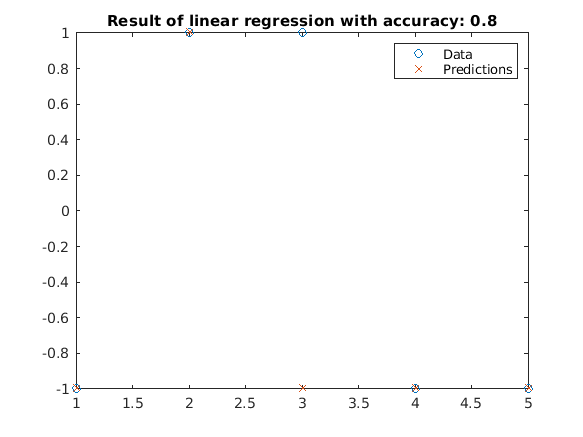


figure,
plot(1:length(y),y,'o',1:length(y),ypred,'x')  
legend('Data','Predictions')
title(['Result of HMC with accuracy: ',num2str(accuracy)]);


%F0
 fa_ac = (yc+pcd).*(ycpred+pred);
 %F01
 fa_ac1 = (yc1+pcd).*(yc1-pcd*log(1));
 %F10
 f1a1_ac = (ycpred-pred*log(1)).*(ycpred+pred);
 %F1
 f1a1_ac1 = (yc-pcd*log(1)).*(ycpred-pred*log(1));

  % fk = (gam(1) - pad(1:4).*log(1.1)).*(gam(2) - pacd(1:4).*log(1.1));
F0 = [mean(fa_ac(:)), mean(fa_ac1(:))];
F1 = [mean(f1a1_ac(1)), mean(f1a1_ac1(1))];
 

nH = sum([ttest(F0(1),F1(1))==0 ,ttest(F0(2),F1(1))==0 ,ttest(F0(1),F1(2))==0 ,ttest(F0(2),F1(2))==0]);
phi =  3/4+0.5*nH/4;
psi = 0.5+0.5*(3/4-1/4);
 
phi_ = mean(F0(:))-mean(F1(:))+0.5

phi_ = 1.0897

psi_ = max(F0(:)-F1(:))

psi_ = 0.8635

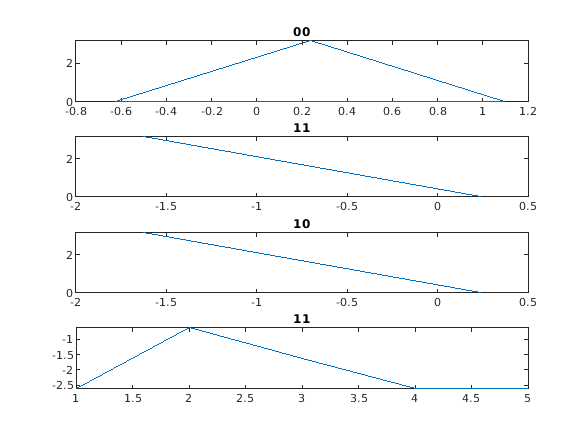

 
figure,
subplot(4,1,1)
plot(log(fa_ac));
title('00');
subplot(4,1,2)
plot(log(fa_ac1));
title('11');
subplot(4,1,3)
plot(log(f1a1_ac));
title('10');
subplot(4,1,4)
plot(log(f1a1_ac1));
title('11');

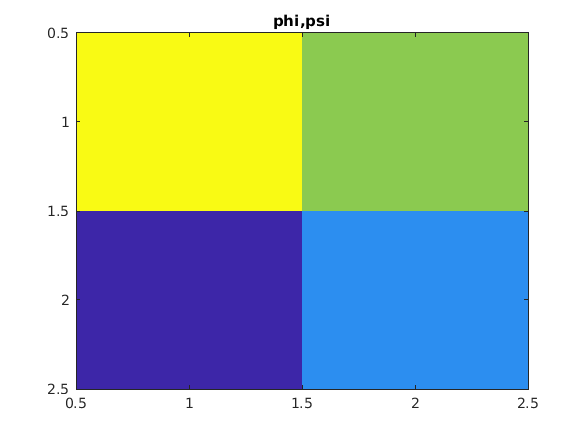

figure,
imagesc([F0;F1])
title('phi,psi')

eps0 = 0.01;
w = ones(M, 1)/M;
lmd = w;
%threshold1 = 80;
%threshold2 = 120;
%fn = 0:bin-1;
%f = 1.0*double(fn)/double(bin-1);
%t = -0.5:1/bin:0.5;  % Time vector 
%L = length(t)-1;      % Signal length
%X = 1/(4*sqrt(2*pi*0.01))*(exp(-t(1:L).^2/(2*0.01)));
%fX = fft(MEA_ch(1: bin: Pnts)).*X;
%ni = find(MEA_ch > threshold);
steps = 50;  
Ll = repmat(-100,[M, 1]);
ll = zeros(M, N);
lt = zeros(M, N);
ypredl = zeros(1, N);
W = zeros(M, N);
B = zeros(M, N);
F_= zeros(M, N);
Test = normpdf(SEtemp, mean(SEtemp), std(SEtemp));
clear SEtemp ;
SEtemp = Test;
% Mu = ze(length(ctx), 1);
% Eta = zeros(idN, idN);
% Kse = zeros(idN, idN);
    for k = 1:N
%    k = 1;
%    for k =
%    1:length(ctx)
%    for k = 1:7
%    for k = 59:length(ctx) 
%for k = 54:length(ctx);
        Y = y(k);
        SEtemp = SE(:,k); 
        SEtemp = (SEtemp - mean(SEtemp))/std(SEtemp);
        while steps >0

            b = gampdf(SEtemp, 0.2, 2);
%             b = ones(length(F_(:, k)),1)./(1 + exp(-F_(:, k) - sigma.*F_hat));
            w = w/(sum(w)+0.000001);
%             wd = 1+exp(-F_);
%             wd(isinf(wd)) = 10000;
%             w = w + mu*F_hat.*wd.^2./(exp(-F_(:, k)).*F_+0.00001);
%             b = b + mu*F_hat.*wd.^2./(exp(-F_(:, k)-sigma.*F_hat).*F_+0.00001);   
            K =  abs(SEtemp); 
            ll(1:length(K), k) = log(1 + exp(-Y.* w(1:length(K)).* SEtemp(:))) + lmd(1:length(K)).*w(1:length(K)).^2/2 + 2*K.*b.* SEtemp./(eps0*length(K));
            cond = log(1 + exp(-Y.* w(1:length(K)).* SEtemp)) + lmd(1:length(K)).*w(1:length(K)).^2/2 + 2*K.*b.* SEtemp./(eps0*(1:length(K)))> Ll(1:length(K));
            if sum(isnan(cond))~= length(cond) & sum(cond==0)~= length(cond)
                W(1:length(K),k) = -Y.*SEtemp./(1 + exp(-Y.* w(1:length(K)).* SEtemp));
            end
            
            if (sum(isnan(cond))== length(cond) | sum(cond==0)== length(cond)) 
                k = k+1;
                steps = 50;
                break;
            end
            w = W(:, k);
            Ll = log(1 + exp(-Y.* w(1:length(K)).* SEtemp)) + lmd.*w(1:length(K)).^2/2 + 2.*K.*b(1:length(K)).* SEtemp./(eps0*(1:length(K)));
            steps = steps -1;
            if steps == 0
                ll(isnan(ll(:,k)),k) = 0.5*ll(isnan(ll(:,k)),max(k-1,1))+0.5*ll(isnan(ll(:,k)),min(k+1,N));
                ll(sum(isnan(ll(:,k)),k)==size(ll,1),k) = 0.5*ll(sum(isnan(ll(:,k)))==size(ll,1),max(k-1,1))+0.5*ll(sum(isnan(ll(:,k)))==size(ll,1),min(k+1,N));
                ypredl(k) = mean(ll(ll(:,k)~=0,k));
                k = k+1;
                steps = 50;
                break;
            end
%             if k > length(ctx)
%                  break
%             end
        end
    end
    ypredl

ypredl =     0.3068    0.6944    0.6946    0.6947    0.6946


     ypredl(ypredl>mean(ypredl)) = 1;
     ypredl(ypredl<=mean(ypredl))  = -1;
     accuracy = (sum(ypredl == y))./length(y)

accuracy = 0.6000